# 9주차 — 안정 여유: -1 점에서 얼마나 떨어져 있는가

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

**1. 올해(2026) 수업 — 항상 이 두 곳에 올라옵니다**

수업이 끝나면 그날 녹화가 재생목록에 올라가고, 자료를 고치면 GitHub 이 곧바로 갱신됩니다. **빠진 수업이 있거나 따라가지 못한 곳이 있으면 이 둘을 먼저 보십시오.** 강의노트 · 실습 스크립트 · Simulink 모델 · 숙제가 모두 GitHub 에 있습니다.

**2. 담당교수가 직접 한 강의 다섯 과목**

기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**3. MATLAB 이나 Simulink 가 아직 익숙하지 않다면**

실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

지난 주에는 주파수응답이 **어떻게 생겼는지**를 봤습니다. 오늘은 그 그림으로 **안정한지 아닌지, 그리고 얼마나 여유가 있는지**를 판단합니다.

5주차에서도 안정도를 다뤘습니다. 그때는 극점이 좌반면에 있는지를 봤습니다. 오늘 방법이 그것보다 나은 점은 두 가지입니다.

- **모델이 없어도 된다.** 실험으로 잰 보드 선도만 있으면 판단할 수 있다

- **얼마나 여유가 있는지 숫자로 준다.** 안정한가 아닌가만이 아니라 "얼마나 더 나빠져도 버티는가" 를 알려 준다

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W09_Nyquist_Margin` 폴더 안에 있습니다.

그리고 **블록이 다섯 개뿐인 작은 모델 네 개**가 따로 있습니다. `W09_Margin_Check.slx` 는 선형화까지 다루는 "본 모델" 이라 처음 보면 복잡합니다. 아래 넷은 **하나가 한 가지만** 보여 주고, 서로 아무 관계가 없습니다. 따로 열어 그냥 실행만 누르면 됩니다.

**0-4절을 먼저 읽고 이 네 개를 돌려 본 다음 1절로 가십시오.** 오늘의 이론은 전부 이 네 실험의 설명입니다.

뒤의 세 파일(`W09_04` ~ `W09_06`)은 **공통 함수를 쓰지 않습니다.** `tf`, `feedback`, `margin`, `step` 같은 MATLAB 기본 명령만으로 적어 두었으니 절마다 따로 떼어 돌려 보십시오.

오늘 처음 쓰는 도우미 함수도 하나 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**개루프의 크기가 **$1$** 이고 위상이 **$-180^\circ$** 이면 폐루프가 불안정해진다. 그 점에서 얼마나 떨어져 있는가가 곧 안정 여유다.**

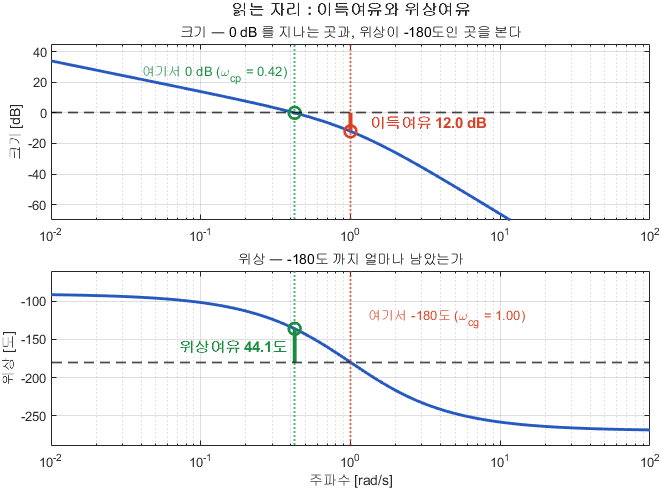

보드 선도에서 이득여유와 위상여유를 읽는 자리

**그림 파일** `w09_margin_read.png` — `common/dg_margin.m` 의 `dg_margin` · 다시 만들려면 `make_figures('w09_margin_read')`

**만드는 곳** — `common/dg_margin.m` (`make_figures('w09_margin_read')`). 명령창에서 `dg_margin(0.5/(s*(s+1)^2))` 처럼 다른 시스템으로 불러도 됩니다 **직접 해 보려면** — `W09_01_nyquist_margin.m` 의 **3절**이 같은 값을 `margin` 으로 뽑아 표로 찍어 줍니다

그림 해석 — **이 표를 그대로 읽으면 3절 설명이 됩니다**

학생들이 가장 많이 틀리는 것이 이 **교차**입니다. $-180^\circ$ 를 아래에서 찾아 **위에서** 읽으면 GM, $0$ dB 를 위에서 찾아 **아래에서** 읽으면 PM 입니다.

오늘의 계단

절이 많습니다. 그래서 **반드시 읽을 것**과 **더 알고 싶을 때 읽을 것**을 나눠 두었습니다. 아래 일곱 절만 읽어도 오늘의 목표는 달성됩니다.

아래는 **시험에 꼭 나오는 것은 아니지만** 왜 그렇게 되는지 궁금할 때 읽는 절입니다. 한 번에 다 읽으려 하지 말고 필요할 때 찾아 오십시오.

어느 절이 강의자료 몇 쪽인지는 **0-3절의 대응표**에 있습니다.

## 0-1. 가장 작은 예부터 — 마이크와 스피커

강의실에서 마이크를 스피커 쪽으로 돌리면 "삐-" 하고 울립니다. 이것이 바로 오늘의 주제입니다.

무슨 일이 일어난 것인가.

- 스피커 소리가 마이크로 **되돌아온다** (피드백 루프가 생겼다)

- 어떤 특정 주파수에서 **소리가 줄지 않고 그대로 돌아온다** (크기 $= 1$)

- 그리고 그 주파수에서 **위상이 딱 맞아떨어진다** (위상 $= -180^\circ$)

그러면 그 주파수의 소리가 스스로 유지되고 커집니다. 그것이 하울링입니다.

마이크를 멀리 두면 안 울립니다. 되돌아오는 소리가 작아져 **크기 조건을 못 맞추기 때문**입니다. 그 여유가 곧 **이득여유**입니다.

## 0-2. 왜 하필 $-1$ 인가 — 신호를 따라가 보면

공식으로 외우기 전에 **신호가 한 바퀴 도는 것**을 직접 보십시오.

되먹임 루프에서 오차 $e$ 는 $L$ 을 지나 되돌아와 다시 $e$ 에 더해집니다. 그런데 되먹임은 **빼기**이므로, 돌아온 신호의 위상이 $-180^\circ$ 라면 빼기와 뒤집힘이 겹쳐 **원래 신호와 같은 부호로 더해집니다.**

그때 크기가 $1$ 보다 크면 매 바퀴마다 커지고, 작으면 매 바퀴마다 줄어듭니다.

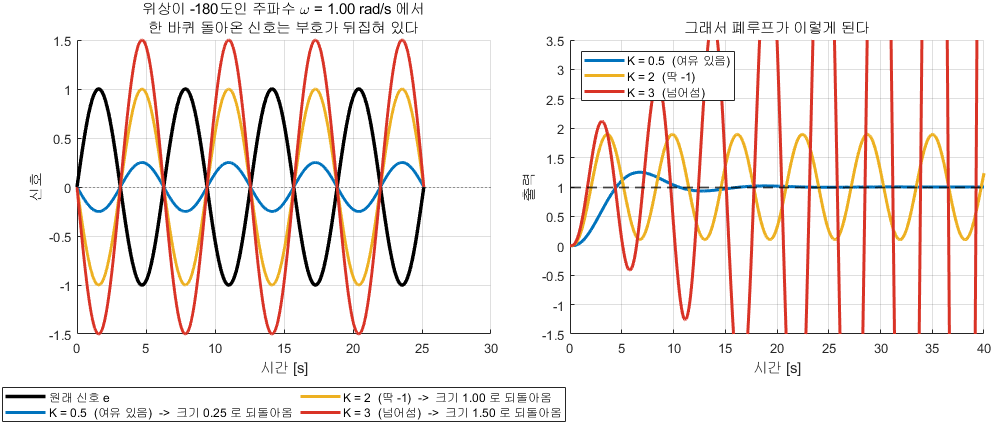

-180도 주파수에서 한 바퀴 돌아온 신호의 크기가 전부를 정한다

**그림 파일** `w09_why_minus1.png` — `make_figures.m` 의 `fig_w09_why_minus_one` · 다시 만들려면 `make_figures('w09_why_minus1')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_why_minus_one` **직접 바꿔 보려면** — 함수 안의 `Ks = [0.5 2 3]` 에 $1.0$ 을 추가해 보십시오

그림 해석

**왼쪽의 진폭 하나가 오른쪽의 운명을 정합니다.** 그 진폭이 정확히 $|L(j\omega)|$ 이고, 그것이 $1$ 이 되는 자리가 $-1$ 점입니다.

## 0-3. 강의자료와 이 노트의 대응

이 노트는 교수자 강의자료 `06_FrequencyResponse` 의 **29~72쪽**을 하나도 빠뜨리지 않고 옮긴 것입니다 (1~16쪽은 8주차에 있습니다). 강의 중에 슬라이드를 띄우고 "이건 노트 몇 절" 을 찾을 때 쓰는 표입니다.

강의자료에 있는 **MATLAB 코드는 전부 실습 스크립트로 옮겼습니다.** 슬라이드의 코드를 그대로 베끼지 않고, 절마다 따로 떼어 돌릴 수 있도록 다시 적었습니다 (`W09_04`, `W09_05`, `W09_06`).

## 0-4. 손으로 먼저 — 블록 다섯 개짜리 모델 네 개

1절부터는 식이 나옵니다. 그 전에 **손으로 한 번 돌려 보고 갑니다.**

왜 이 순서인가. 오늘 배울 것은 전부 "신호가 루프를 한 바퀴 돌면 어떻게 되는가" 한 가지입니다. 그런데 그것을 식으로 먼저 보면 $1 + L(s) = 0$ 이라는 글자만 남습니다. **한 바퀴 돌려 보면 그 자리에서 보입니다.**

네 모델이 쓰는 플랜트는 **전부 같습니다.** 달라지는 것은 연결 하나와 손잡이 하나뿐입니다. 그것이 이 네 실험의 요점입니다.


$$G(s) = \frac{1}{s(s+1)^2}$$


왜 이 플랜트인가 — **손으로 계산이 되기 때문입니다.** $\omega = 1$ 을 넣어 봅니다.

1단계. 괄호를 먼저 펼칩니다.


$$(j+1)^2 = j^2 + 2j + 1 = -1 + 2j + 1 = 2j$$


2단계. 앞의 $s = j$ 를 곱합니다.


$$j \cdot 2j = 2j^2 = -2$$


3단계. 역수를 취합니다.


$$G(j1) = \frac{1}{-2} = -0.5$$


결과를 말로 옮기면 이렇습니다.

- 크기는 $0.5$ — **신호를 반으로 줄인다**

- 실수이고 음수 — **위아래가 뒤집힌다.** 즉 위상이 정확히 $-180^\circ$

이 한 줄이 오늘 네 실험 전체의 출발점입니다.

손계산을 MATLAB 으로 검산합니다 (네 모델이 쓰는 그 플랜트입니다)

G = 1/(s*(s+1)^2);
disp(['G(j1) = ' num2str(freqresp(G,1))])
disp(['크기 = ' num2str(abs(freqresp(G,1))) ',  위상 = -180 도'])

## 0-4-1. 첫 번째 모델 — 루프를 끊고 한 바퀴만

모델 `W09_E1_LoopOnce.slx` 에는 **되먹임선이 없습니다.** 신호가 한 번만 지나갑니다.

사인 $\rightarrow$ 이득 $K$ $\rightarrow$ 플랜트 $G$ $\rightarrow$ 출력, 끝입니다.

여기에 $\omega = 1$ 사인을 넣으면 나오는 진폭은 손계산으로 이렇습니다.


$$\text{나오는 진폭} = K \cdot |G(j1)| = 0.5 K$$


이 값에 이름이 붙어 있습니다. **루프이득** $L = KG$ 의 크기입니다.

그리고 세 경우 모두 **위아래가 뒤집혀** 돌아옵니다.

진폭을 재는 법 — 이 플랜트는 적분기 $1/s$ 를 가지고 있어서 출력에 **일정한 치우침**이 생깁니다. 그래서 최댓값만 보면 안 되고 최댓값에서 최솟값을 빼 $2$ 로 나눠야 합니다. 치우침이 저절로 빠집니다.

**직접 해 보려면** — `W09_07_examples.m` 의 **1절**이 이 표를 그대로 찍어 줍니다.

## 0-4-2. 두 번째 모델 — 되먹임선 하나만 더 긋는다

모델 `W09_E2_GainMargin.slx` 는 **E1 과 블록이 똑같습니다.** 더해진 것은 플랜트 출력에서 오차로 돌아가는 선 하나뿐입니다. 그런데 결과는 완전히 달라집니다.

왜 달라지는가. 되먹임의 빼기가 **한 번 더 뒤집기** 때문입니다.

- E1 에서 돌아온 신호는 이미 뒤집혀 있다 (위상 $-180^\circ$)

- 오차에서 한 번 더 뒤집힌다 (빼기)

- 두 번 뒤집으면 **원래 신호와 같은 방향**이다

즉 돌아온 신호가 자기 자신을 **보태 줍니다.** 그러면 남은 문제는 크기뿐입니다.

그러므로 안정 한계는 $0.5K = 1$, 즉 $K = 2$ 입니다. **E1 을 한 번 돌려 보면 E2 의 결과를 미리 알 수 있습니다.** 이것이 오늘 배우는 모든 것의 알맹이입니다.

그리고 이 "몇 배까지 키워도 되는가" 에 붙은 이름이 **이득여유**입니다. 지금 $K = 0.5$ 라면 $2 / 0.5 = 4$ 배, 데시벨로는 $20\log_{10}4 = 12$ dB 입니다.

손계산 확인 — K 를 바꿔 가며 루프이득의 크기만 본다

for Kk = [0.5 2 3]
    disp(['K = ' num2str(Kk) ' :  루프이득 크기 = ' ...
          num2str(abs(freqresp(Kk*G,1))) ])
end

## 0-4-3. `Transport Delay` — 오늘의 새 Simulink 블록

세 번째 모델에 새 블록이 하나 나옵니다. **블록을 먼저 설명하고 모델로 갑니다.**

블록 정리

- **원리** — 들어온 신호를 정해진 시간만큼 **그대로 늦춰** 내보낸다. 모양을 바꾸지 않고 시간축에서 오른쪽으로 밀기만 한다. 수식으로는 $y(t) = u(t - \tau)$ 이고, 라플라스 영역에서는 $e^{-s\tau}$ 다

- **입력** — 늦출 신호 하나

- **출력** — $\tau$ 초 전의 입력값. 시작 직후 $\tau$ 초 동안은 초기값을 낸다

- **파라미터** — `Delay time` 에 $\tau$ (초). `Initial input` 은 시작 $\tau$ 초 동안 내보낼 값 (기본 $0$)

주의 세 가지

- `Delay time` 에 $0$ 을 넣으면 Simulink 가 "직접 피드스루로 바꿨다" 는 **경고**를 냅니다. 결과에는 문제가 없는 안내입니다

- 이 블록은 **유리함수가 아닙니다.** 그래서 전달함수로 적을 수 없고, 극점이 무한히 많습니다. 근궤적으로 다루기 어려운 이유가 이것입니다

- `linearize` 는 기본적으로 이 블록을 **이득 **$1$** 로** 근사해 버립니다. 그러면 "지연을 넣었는데 위상여유가 안 변한다" 는 이상한 결과가 나옵니다. 피하는 법은 6-1절에 있습니다

왜 이 블록을 오늘 배우는가 — **주파수영역 방법의 가장 큰 장점**이 여기서 나옵니다. 지연의 주파수응답을 보면 그 이유가 바로 보입니다.


$$e^{-j\omega\tau} \qquad \Rightarrow \qquad |e^{-j\omega\tau}| = 1, \quad \angle e^{-j\omega\tau} = -\omega\tau \ \text{[rad]}$$


왜 크기가 $1$ 인가 — 오일러 공식으로 풀면 $e^{-j\theta} = \cos\theta - j\sin\theta$ 이고, 그 크기는 $\sqrt{\cos^2\theta + \sin^2\theta} = 1$ 입니다. $\theta$ 가 무엇이든 $1$ 입니다.

결론 두 줄 —

- 지연은 **크기 곡선을 전혀 건드리지 않는다**

- 위상만 $-\omega\tau$ 만큼 깎고, 그 값이 $\omega$ 에 비례하므로 **고주파일수록 심하게** 깎인다

지연의 크기가 정말 1 인지 확인한다 (어떤 주파수에서든)

for ww = [0.1 1 10]
    disp(['w = ' num2str(ww) ' :  지연 1초의 크기 = ' num2str(abs(exp(-1j*ww*1))) ...
          ',  위상 = ' num2str(-ww*180/pi) ' 도'])
end

## 0-4-4. 세 번째 모델 — 이득은 그대로, 지연만 키운다

모델 `W09_E3_DelayMargin.slx` 는 E2 에 **지연 블록 하나만** 끼워 넣은 것입니다. 그리고 이번에 바꾸는 손잡이는 $K$ 가 **아닙니다.** $K$ 는 $0.5$ 로 고정합니다.

앞 절에서 본 대로 지연은 크기를 건드리지 않습니다. 그러므로 이득여유는 이 실험을 설명하지 못합니다. 깎이는 것은 **위상**뿐입니다.

그러면 얼마까지 깎여도 되는가. 가장 위험한 자리는 **크기가 이미 **$1$** 인 주파수**입니다. 거기서 위상까지 $-180^\circ$ 에 닿으면 바로 E2 의 지속진동 조건이 됩니다. 그 주파수를 $\omega_{cp}$ 라고 부릅니다.

유도는 한 줄입니다. 지연이 $\omega_{cp}$ 에서 깎는 위상이 남은 위상여유와 같아지는 순간이 한계입니다.


$$\omega_{cp}\,\tau = PM \ \text{[rad]} \qquad \Rightarrow \qquad \tau_{max} = \frac{PM \ \text{[rad]}}{\omega_{cp}}$$


$K = 0.5$ 인 이 시스템은 $PM = 44.1^\circ$, $\omega_{cp} = 0.424$ rad/s 이므로


$$\tau_{max} = \frac{44.1 \times \pi / 180}{0.424} \approx 1.81 \ \text{s}$$


**이 설계는 1.81 초까지의 지연은 견딥니다.** 그보다 늦으면 발산합니다. 그래서 위상여유를 이렇게 읽어도 됩니다 — **얼마나 늦어도 되는가를 재는 자.**

손계산 검산

[gm0, pm0, wcg0, wcp0] = margin(0.5*G);
disp(['GM = ' num2str(gm0) ' 배 (' num2str(20*log10(gm0)) ' dB)'])
disp(['PM = ' num2str(pm0) ' 도,  wcp = ' num2str(wcp0) ' rad/s'])
disp(['견디는 지연 tau_max = ' num2str(deg2rad(pm0)/wcp0) ' 초'])

## 0-4-5. 네 번째 모델 — 폐루프에 사인을 넣어 빠르기를 잰다

앞의 세 실험은 모두 **개루프** 이야기였습니다. 네 번째는 루프를 닫고 잽니다.

왜 또 재는가. 지금까지 구한 GM 과 PM 은 **안전한가**에 대한 답입니다. 그런데 설계에는 질문이 하나 더 있습니다 — **빠른가.** 그 답이 폐루프의 주파수응답에 들어 있습니다.

재는 방법은 8주차에서 플랜트의 보드 선도를 사인으로 쟀던 그 방법 그대로입니다.

- 사인 하나를 넣는다

- 과도구간이 지난 뒤 **나온 사인의 진폭**을 잰다

- 넣은 진폭으로 나눈다. 그것이 그 주파수의 폐루프 크기다

모델 `W09_E4_Bandwidth.slx` 에서 `w_in` 을 하나씩 바꿔 넣으면 두 가지 숫자가 보입니다.

왜 하필 $0.707$ 인가 — 전력이 절반이 되는 지점입니다. $20\log_{10}(1/\sqrt{2}) = -3$ dB 이고, $1/\sqrt{2} = 0.707$ 입니다.

$K = 0.5$ 에서 실제로 재면 $M_r = 1.31$ ($\omega = 0.4$ 근처), $\omega_{BW} = 0.75$ rad/s 가 나옵니다.

여기서 눈여겨볼 것이 하나 있습니다. 개루프 교차주파수는 $0.424$ 였는데 폐루프 대역폭은 $0.750$ 입니다. **폐루프가 개루프보다 넓습니다.** 둘은 이름이 다른 두 주파수이고, 그 관계는 4-3절과 5-1-3-2절에서 다룹니다.

손계산 검산 — 폐루프를 만들어 바로 재 본다

T0 = feedback(0.5*G, 1);
disp(['공진봉우리 Mr = ' num2str(max(abs(freqresp(T0, logspace(-1,0.5,300)))))])
disp(['대역폭 w_BW = ' num2str(bandwidth(T0)) ' rad/s'])
disp(['개루프 교차주파수 w_cp = ' num2str(wcp0) ' rad/s'])

% 0-4절에서 쓴 임시 변수를 지웁니다. 1절부터는 다시 처음부터 세웁니다.
clear G Kk ww T0 gm0 pm0 wcg0 wcp0

## 0-4-6. 네 실험이 오늘의 지도다

방금 돌려 본 네 가지가 오늘 배울 것의 전부입니다. 1절부터는 **이 네 가지를 식으로 다시 쓰는 일**을 합니다.

오른쪽 두 칸이 낯설어 보이면 **왼쪽 칸을 떠올리십시오.** 식이 어려워질 때마다 돌아와 모델을 한 번 더 돌려 보면 됩니다.

## 1. 불안정의 조건

단위 피드백 폐루프는 이렇습니다.


$$T(s) = \frac{L(s)}{1 + L(s)}$$


분모가 $0$ 이 되는 $s$ 가 폐루프 극점이므로


$$1 + L(s) = 0 \qquad \Rightarrow \qquad L(s) = -1$$


$s = j\omega$ 로 놓고 읽으면 이렇습니다.


$$|L(j\omega)| = 1 \quad\text{이면서}\quad \angle L(j\omega) = -180^\circ$$


**왜 이것이 위험한가 — 이유가 두 가지입니다**

**이유 1. 폐루프 이득이 무한대가 됩니다.**

$T$ 의 분모를 그대로 보십시오.


$$T(j\omega) = \frac{L(j\omega)}{1 + L(j\omega)}$$


$L(j\omega) = -1$ 을 대입하면 분모가 이렇게 됩니다.


$$1 + L(j\omega) = 1 + (-1) = 0$$


즉 $T$ 는 $\frac{-1}{0}$ 입니다. **0 으로 나누는 것**이므로


$$|T(j\omega)| \rightarrow \infty$$


이것이 무슨 뜻인가 — $T$ 는 "지령 $1$ 을 넣으면 출력이 얼마냐" 를 재는 값입니다. 그 값이 무한대라면 **지령을 아주 조금만 넣어도 출력이 무한히 커진다**는 말이고, 거꾸로 읽으면 **입력이 없어도 그 주파수의 출력이 저절로 난다**는 말입니다. 그것이 바로 불안정입니다.

**이유 2. **$-1$** 은 두 군데에서 옵니다. 그리고 그 둘이 곱해집니다.**

- 위상이 $-180^\circ$ 라는 것은 한 바퀴 돌아온 신호가 **뒤집혀 왔다**는 뜻, 곧 $-1$ 을 곱한 것입니다

- 되먹임의 합산점은 **빼기**입니다. 거기서 $-1$ 을 한 번 더 곱합니다

- 둘을 곱하면 $(-1)\times(-1) = +1$ 입니다

그러므로 돌아온 신호가 **원래 신호와 똑같은 부호로 더해집니다.** 거기에 크기까지 $1$ 이면 줄지도 늘지도 않고 **계속 돕니다.** 크기가 $1$ 보다 크면 돌 때마다 커집니다.

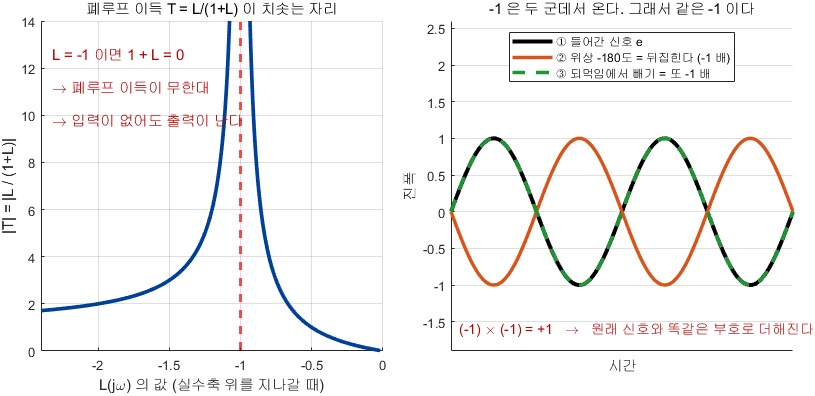

-1 점에서 폐루프 이득이 치솟는 이유와 -1 이 두 군데서 오는 이유

**그림 파일** `w09_why_unstable.png` — `make_figures.m` 의 `fig_w09_why_unstable` · 다시 만들려면 `make_figures('w09_why_unstable')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_why_unstable` **직접 확인해 보려면** — `W09_04_gm_pm_build.m` 의 **1절**

그림 해석

이 두 조건을 동시에 만족하는 주파수가 있으면 그 주파수로 진동합니다.

왼쪽 그림의 치솟음을 **숫자 세 개로** 확인해 봅니다.

L_vals = [-0.9; -0.99; -1.001];     % -1 에 점점 가까이 가는 L 값
T_vals = L_vals ./ (1 + L_vals);    % 폐루프 이득 T = L/(1+L)
table(L_vals, T_vals)

$-1$ 에 가까워질수록 폐루프 이득이 커집니다. $L = -1.001$ 에서는 부호까지 뒤집힌 $1000$ 배가 나옵니다. $-1$** 을 지나는 순간 무언가 극적인 일이 일어난다는 것**을 이 세 숫자가 보여 줍니다.

## 1-1. 숫자로 확인

강의자료 6장의 표준 예제로 확인합니다.


$$L(s) = \frac{K}{s\,(s+1)^2}$$


G = 1/(s*(s+1)^2);
K = [0.5 1 2 3]';
max_real = zeros(size(K));            % 폐루프 극점 실수부의 최댓값
for i = 1:numel(K)
    max_real(i) = max(real(pole(feedback(K(i)*G, 1))));
end
stable = max_real < 0;                % 전부 좌반면이면 안정
table(K, max_real, stable)

실수부 최댓값이 $0$ 을 넘는 순간 불안정해집니다. 이 시스템은 $K = 2$ 가 안정 한계이고, **5주차에서 라우스 표로 구했던 임계이득과 같은 값**입니다.

## 2. 나이퀴스트 선도

보드 선도는 크기와 위상을 **따로** 그렸습니다. 나이퀴스트 선도는 둘을 **한 평면에** 그립니다.

$\omega$ 를 훑으며 복소수 $L(j\omega)$ 를 복소평면에 찍는 것뿐입니다. 그러면 "$-1$ 이 되는가" 를 눈으로 볼 수 있습니다.

보드 선도와 나이퀴스트 선도는 **같은 정보를 다르게 그린 것**입니다.

그래서 "크기 $1$, 위상 $-180^\circ$" 라는 두 조건이 나이퀴스트 선도에서는 **점 하나**($-1$)가 됩니다. 이것이 오늘 이 그림을 쓰는 이유입니다.

## 2-0. `nyquist` — 오늘의 새 명령

- **원리** — $\omega$ 를 $-\infty$ 에서 $+\infty$ 까지 훑으며 복소수 $L(j\omega)$ 를 복소평면에 찍는다

- **입력** — **개루프** 전달함수 $L$. `margin` 과 같습니다

- **출력** — 받지 않으면 그림. `[re, im] = nyquist(L, w)` 로 값도 받을 수 있다

주의 네 가지

- **폐루프를 넣으면 안 됩니다.** $-1$ 점 판정은 개루프에 대한 것입니다

- 그림에 `-1` 자리를 표시해 주지 않습니다. `hold on` 하고 직접 찍으십시오

- $\omega$ 가 음수인 쪽까지 그리므로 **곡선이 실축 기준으로 대칭**입니다. 두 겹으로 보이는 것이 정상입니다

- **원점에 극점(적분기)이 있으면 곡선이 무한대로 날아가** 그림이 깨집니다. 그때는 `common/` 의 `nyquist1` 을 쓰십시오. $j\omega$ 축을 살짝 우회해 그려 줍니다

값을 받아 쓰는 예 — $-1$ 점까지의 **최단 거리**를 재 봅니다. 이 거리가 곧 "얼마나 아슬아슬한가" 입니다.

s = tf('s');
G_ex = 1/(s*(s+1)^2);
w_ex = logspace(-1, 1, 2000);
[re_ex, im_ex] = nyquist(0.5*G_ex, w_ex);
re_ex = squeeze(re_ex);  im_ex = squeeze(im_ex);
distance = min(hypot(re_ex + 1, im_ex))   % 궤적과 -1 점의 최단 거리

이 거리가 **작을수록 불안정에 가깝습니다.** 5절에서 배울 감도 최대값은 이 거리의 역수입니다.

peak_sensitivity = 1/distance

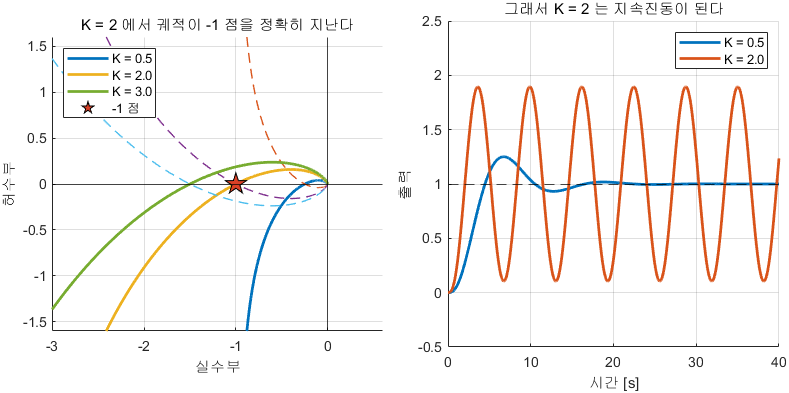

K = 2 에서 궤적이 -1 점을 정확히 지난다

**그림 파일** `w09_nyquist_K.png` — `make_figures.m` 의 `fig_nyquist_K` · 다시 만들려면 `make_figures('w09_nyquist_K')`

**만드는 곳** — `make_figures.m` 의 `fig_nyquist_K` **직접 바꿔 보려면** — `W09_01_nyquist_margin.m` 의 **2절**에서 `Ks` 를 바꿔 실행. `nyquist1` 을 쓰면 적분기가 있어도 깔끔하게 그려 줍니다

그림 해석

**보드 선도의 두 그림을 한 장으로 접은 것**이 나이퀴스트 선도입니다. 원점에서의 거리가 크기, 각도가 위상입니다. 그래서 "크기 $1$, 위상 $-180^\circ$" 가 이 그림에서는 **점 하나**가 됩니다.

## 2-0-1. 그런데 왜 $\omega$ 를 음수까지 훑는가 — 나이퀴스트 경로

앞 절의 주의에서 "곡선이 실축 기준으로 대칭이라 두 겹으로 보인다" 고 했습니다. 그것이 왜 그런지, 그리고 애초에 왜 그렇게 그리는지 짚고 갑니다. **이 절을 건너뛰면 다음 절의 판정법이 마술처럼 보입니다.**

우리가 알고 싶은 것은 **폐루프 극점이 우반면에 있는가**입니다. 폐루프 극점은 $1 + L(s) = 0$ 의 근이므로, 결국 **"**$1+L(s)$** 가 우반면에서 **$0$** 이 되는 곳이 있는가"** 를 묻는 것입니다.

복소해석에는 이런 질문에 답하는 도구가 있습니다. **어떤 닫힌 길을 따라 함수값이 원점을 몇 바퀴 도는지 세면, 그 길 안에 영점과 극점이 각각 몇 개 있는지 알 수 있습니다.** 이것이 **편각원리**입니다.

그래서 **우반면 전체를 감싸는 닫힌 길**을 만듭니다. 그 길이 두 부분입니다.

- **허수축** — $s = j\omega$ 로 $\omega$ 를 $-\infty$ 에서 $+\infty$ 까지

- **무한대 반원** — 오른쪽을 크게 돌아 출발점으로 되돌아온다

이 닫힌 길을 **나이퀴스트 경로**라고 합니다.

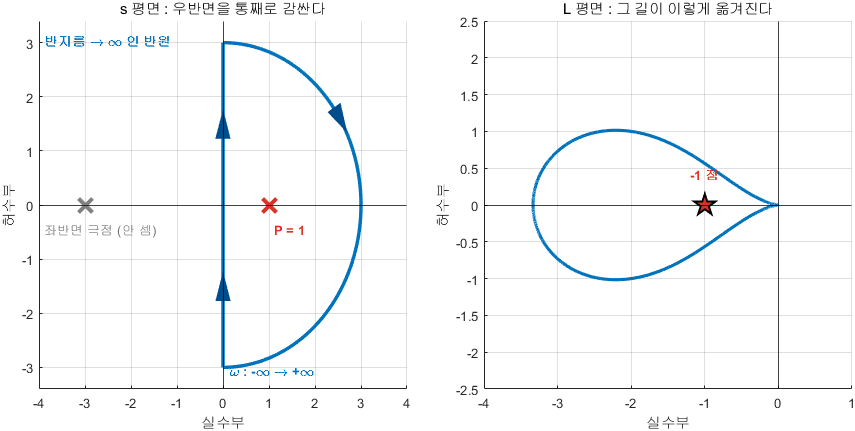

우반면을 감싸는 닫힌 길을 L 로 옮긴 것이 나이퀴스트 선도다

**그림 파일** `w09_contour.png` — `make_figures.m` 의 `fig_w09_contour` · 다시 만들려면 `make_figures('w09_contour')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_contour` **직접 확인해 보려면** — `W09_01_nyquist_margin.m` 의 **2절**

그림 해석

마지막 줄이 "두 겹으로 보인다" 의 정체입니다. 우리가 실제로 계산하는 것은 $\omega > 0$ 쪽 절반뿐이고, 나머지 절반은 **거울에 비친 것**입니다.

그리고 원점에 극점(적분기)이 있으면 그 점이 경로 위에 놓여 버립니다. 편각원리는 경로 **위에** 극점이 있으면 쓸 수 없으므로, 그때는 원점을 아주 작은 반원으로 살짝 우회합니다. `common/nyquist1.m` 이 그 우회를 대신해 줍니다.

## 2-1. 나이퀴스트 판정

바탕은 복소해석의 **편각원리**입니다. 결론만 쓰면 이렇습니다.


$$Z = N + P$$


- $Z$ — 우반면에 있는 **폐루프** 극점 개수 ($0$ 이라야 안정)

- $N$ — 나이퀴스트 선도가 $-1$ 점을 **시계 방향으로** 감은 횟수

- $P$ — 우반면에 있는 **개루프** 극점 개수

실무에서 쓰는 규칙은 대개 한 줄로 줄어듭니다.

**개루프가 안정하면(**$P = 0$**), 나이퀴스트 선도가 **$-1$** 을 감지 않아야 안정하다.**

그러면 왜 굳이 $P$ 까지 따지는 판정을 배우는가 — **개루프가 이미 불안정한 시스템**이 실제로 있기 때문입니다. 거꾸로 선 진자가 그 예이고, 그런 시스템은 오히려 **이득을 충분히 키워야** 안정해집니다.

Gu = 1/((s-1)*(s+3));
pole(Gu)'                    % 개루프 극점. +1 이 있으므로 우반면 극점 P = 1

K = [1 3 5 10]';
Z = zeros(size(K));          % 폐루프 우반면 극점 개수
for i = 1:numel(K)
    Z(i) = sum(real(pole(feedback(K(i)*Gu, 1))) > 0);
end
stable = Z == 0;
table(K, Z, stable)

**이득을 키워야 안정해집니다.** "이득을 키우면 불안정해진다" 는 상식이 항상 맞지는 않습니다.

## 2-1-1. $N$ 을 실제로 세어 본다

위 표는 `pole(feedback(...))` 로 **답을 미리 본 것**입니다. 이제 그림만 보고 $N$ 을 세어 같은 답이 나오는지 확인합니다. **이것이 나이퀴스트 판정을 실제로 쓰는 방법입니다.**

세는 요령

- $-1$ 점에서 아무 방향으로나 **반직선**을 하나 긋는다 (아래쪽이 편하다)

- 곡선이 그 반직선과 만나는 횟수를 센다

- **시계 방향**으로 지나가면 $+1$, **반시계 방향**으로 지나가면 $-1$

- 그 합이 $N$ 이다

반직선의 방향은 아무래도 좋습니다. 답이 같게 나옵니다. 곡선이 $-1$ 을 아예 안 감싸면 $N=0$ 입니다.

이 예제는 $G(s) = \frac{K}{(s-1)(s+3)}$ 이고 $P = 1$ 입니다. $\omega = 0$ 에서 $L(0) = -K/3$ 이므로 곡선은 **음의 실축에서 출발**합니다. 그러므로 $-1$ 이 곡선 안에 들어오는지는 $K/3$ 이 $1$ 보다 큰지로 갈립니다.

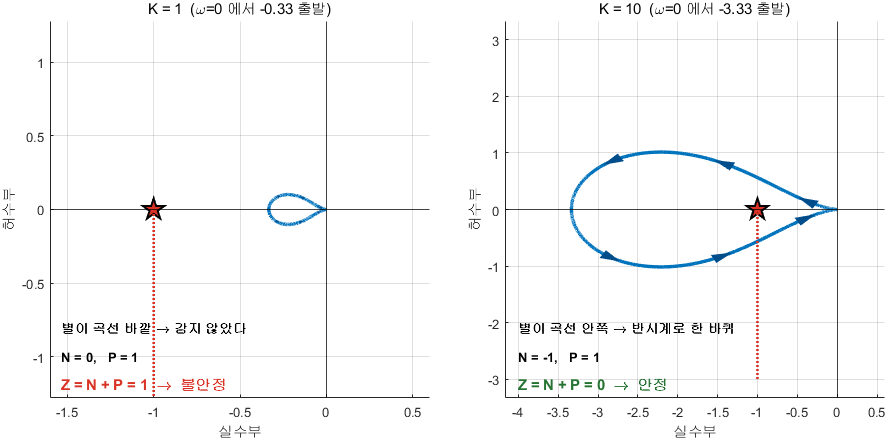

-1 점이 곡선 안에 있는지가 갈랐다

**그림 파일** `w09_encircle.png` — `make_figures.m` 의 `fig_w09_encircle` · 다시 만들려면 `make_figures('w09_encircle')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_encircle` **직접 확인해 보려면** — `W09_01_nyquist_margin.m` 의 **2-1절**에서 `K` 를 $2.9$ 와 $3.1$ 로 바꿔 보십시오. 경계가 정확히 $K=3$ 입니다

그림 해석

**개루프가 불안정하면 **$-1$** 을 "피하는" 것이 아니라 "제대로 감아야" 합니다.** $P=0$ 일 때의 실무 규칙을 그대로 외워 두면 이런 경우에 정반대로 판단하게 됩니다.

아래 코드가 곡선의 왼쪽 끝만 보고 판정합니다. 이 예제는 곡선이 음의 실축에서 출발해 한 바퀴 도는 단순한 모양이라 $-K/3$** 이 **$-1$** 보다 왼쪽인가**만 보면 됩니다.

K  = [1 2.9 3.1 10]';
L0 = -K/3;                        % w = 0 에서 궤적이 있는 자리
N  = -1*(L0 < -1);                % -1 점을 감싸는 횟수 (감싸면 -1)
P  = ones(size(K));               % 개루프 우반면 극점 수
Z  = N + P;                       % 나이퀴스트 판정식
Z_real = zeros(size(K));          % 실제로 세어 본 값
for i = 1:numel(K)
    Z_real(i) = sum(real(pole(feedback(K(i)*Gu, 1))) > 0);
end
table(K, L0, N, P, Z, Z_real)

그림으로 센 $Z$ 와 실제 $Z$ 가 모두 같습니다. 경계는 $-K/3 = -1$, 즉 $K = 3$ 입니다.

## 3. 이득여유와 위상여유

"$-1$ 점에서 얼마나 떨어져 있는가" 를 두 방향으로 나눠 잰 것입니다.

- **이득여유 (GM)** — 위상이 $-180^\circ$ 인 주파수 $\omega_{cg}$ 에서, 크기를 **몇 배** 더 키우면 $1$ 이 되는가

- **위상여유 (PM)** — 크기가 $1$ ($0$ dB) 인 주파수 $\omega_{cp}$ 에서, 위상이 $-180^\circ$ 까지 **몇 도** 남았는가

**읽는 순서를 반드시 기억하십시오.** 학생들이 가장 많이 혼동하기 쉬운 부분입니다.

- 아래 위상 그림에서 $-180^\circ$ 인 곳을 찾는다 $\rightarrow$ $\omega_{cg}$

- 그 주파수에서 **위 크기 그림**을 본다 $\rightarrow$ 이득여유

- 위 크기 그림에서 $0$ dB 인 곳을 찾는다 $\rightarrow$ $\omega_{cp}$

- 그 주파수에서 **아래 위상 그림**을 본다 $\rightarrow$ 위상여유

즉 **한 그림에서 찾고 다른 그림에서 읽습니다.**

K = [0.2 0.5 1 2 3]';
GM = zeros(size(K));  PM = GM;  wcg = GM;  wcp = GM;
ws = warning('off', 'Control:analysis:MarginUnstable');
for i = 1:numel(K)
    [GM(i), PM(i), wcg(i), wcp(i)] = margin(K(i)*G);
end
warning(ws);
GM_dB = 20*log10(GM);
table(K, GM, GM_dB, PM, wcg, wcp)

읽는 법

- $K$ 를 키우면 크기 곡선이 통째로 위로 올라갑니다

- 그래서 **이득여유가 정확히 **$K$** 에 반비례**합니다

- $K = 2$ 에서 $GM = 1$ 배 ($0$ dB), $PM = 0$ 도. **안정 한계**입니다

## 3-1. `margin` — 오늘의 새 명령

명령 정리

- **원리** — 크기가 $0$ dB 를 지나는 곳과 위상이 $-180^\circ$ 를 지나는 곳을 찾는다

- **입력** — **개루프** 전달함수 $L$. 폐루프를 넣으면 안 된다

- **출력** — `[Gm, Pm, Wcg, Wcp]`

주의 세 가지

- `Gm` 은 **배율**이다. dB 로 보려면 `20*log10(Gm)` 을 직접 해야 한다

- 여유가 `Inf` 로 나오는 것은 "무한히 안정" 이 아니라 **그 조건을 만나는 주파수가 없다**는 뜻이다

- 출력을 안 받고 `margin(L)` 만 부르면 그림을 그린다

예제

L1 = 0.5*G;                      % L = 0.5/(s(s+1)^2)
[gm, pm, wcg, wcp] = margin(L1);
gm_dB = 20*log10(gm)             % 이득여유 [dB]
pm                               % 위상여유 [도]

margin(L1); grid on;

## 3-2. 보드 선도에서 여유를 작도하는 세 걸음

`margin` 이 그려 주는 그림을 **손으로 그릴 수 있어야** 시험에서도 쓸 수 있고, 설계할 때 "어디를 얼마나 고칠까" 를 눈으로 가늠할 수 있습니다. 순서는 세 걸음입니다. 그림의 네 칸이 그 순서대로 놓여 있습니다.

**걸음 ①** 이득 $K$ 를 키우면 **크기 곡선이 통째로 위로 올라갑니다.** $20\log_{10}(K\,|G|) = 20\log_{10}K + 20\log_{10}|G|$ 이므로 더해지는 양이 주파수와 무관한 **상수**입니다. 모양은 그대로, 높이만 바뀝니다. 반면 **위상 곡선은 꼼짝도 하지 않습니다** ($\angle(K G) = \angle G$, $K>0$).

이 두 줄을 결론으로 다시 적어 둡니다. 8주차 5-5절에서 유도한 것이고, 오늘 세 걸음 전체가 이 위에 서 있습니다.

- **결론 1 — 크기 선도는 모양이 전혀 바뀌지 않고, 통째로 위아래로만 움직인다.** 올라가는 양은 $20\log_{10}K$ 로 주파수와 무관한 상수다

- **결론 2 — 위상 선도는 **$K$** 를 아무리 바꿔도 전혀 움직이지 않는다** ($K>0$). 양의 실수는 각이 $0^\circ$ 이므로 보탤 위상이 없다

그래서 $K$ 를 키우면 $0$ dB 교차점만 오른쪽으로 밀려가고, 그 자리에서 내려다보는 위상은 더 나빠집니다. **빠르기는 올라가고 위상여유는 깎인다** 는 오늘의 맞바꿈이 여기서 나옵니다 (5-1-5절에서 숫자로 확인합니다).

**걸음 ②** 위상이 $-180^\circ$ 가 되는 주파수 $\omega_{cg}$ 를 아래 칸에서 찾고, 그 주파수의 **위 칸** 값을 읽습니다. $0$ dB 까지 모자란 양이 **이득여유**입니다.

**걸음 ③** 크기가 $0$ dB 가 되는 주파수 $\omega_{cp}$ 를 위 칸에서 찾고, 그 주파수의 **아래 칸** 값을 읽습니다. $-180^\circ$ 까지 남은 각이 **위상여유**입니다.

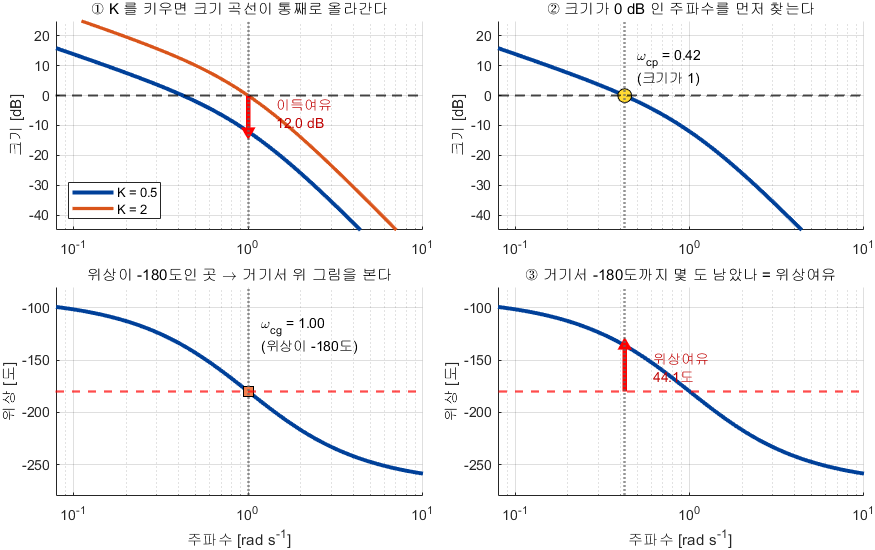

이득여유와 위상여유가 보드 선도에서 만들어지는 과정

**그림 파일** `w09_gm_pm_build.png` — `make_figures.m` 의 `fig_w09_gm_pm_build` · 다시 만들려면 `make_figures('w09_gm_pm_build')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_gm_pm_build` **직접 확인해 보려면** — `W09_04_gm_pm_build.m` 의 **2절**

그림 해석 — **네 칸을 ① → ② → ③ 순서로 보십시오**

마지막 줄이 중요합니다. $K$ 를 바꿔도 $\omega_{cg}$ (위상이 $-180^\circ$ 인 곳)는 제자리이고, 거기서 읽는 크기만 위아래로 움직입니다. **그래서 이득여유는 "**$K$** 를 몇 배 더 키울 수 있는가" 와 정확히 같은 말이 됩니다.**

숫자로 확인합니다. $K=0.5$ 의 이득여유가 $12$ dB, 곧 $4$ 배이므로 $K$ 를 $0.5 \times 4 = 2$ 로 올리면 여유가 $0$ 이 되어야 합니다.

G = 1/(s*(s+1)^2);
[gm_half, pm_half] = margin(0.5*G);
gm_half_dB = mag2db(gm_half)        % K = 0.5 의 이득여유 [dB]
K_limit    = 0.5*gm_half            % 여유를 다 쓰면 K 가 얼마가 되는가

예상대로 $2$ 가 나옵니다. **1-1절의 표에서 안정 한계로 나온 그 값**입니다. 라우스 표(5주차) · 나이퀴스트 선도(2절) · 이득여유(3절) 세 가지 방법이 모두 같은 $K = 2$ 를 가리킵니다.

## 3-3. 이득 세 개로 안정 한계를 통과해 본다

이제 $K$ 를 안정 한계 아래 · 위 · 정확히 그 자리로 두고, **세 가지 그림이 전부 같은 이야기를 한다**는 것을 확인합니다.

**여유가 음수라는 것은 "이미 넘었다" 는 뜻입니다.** $-3.5$ dB 는 "불안정에서 벗어나려면 이득을 $3.5$ dB 줄여야 한다" 로 읽습니다.

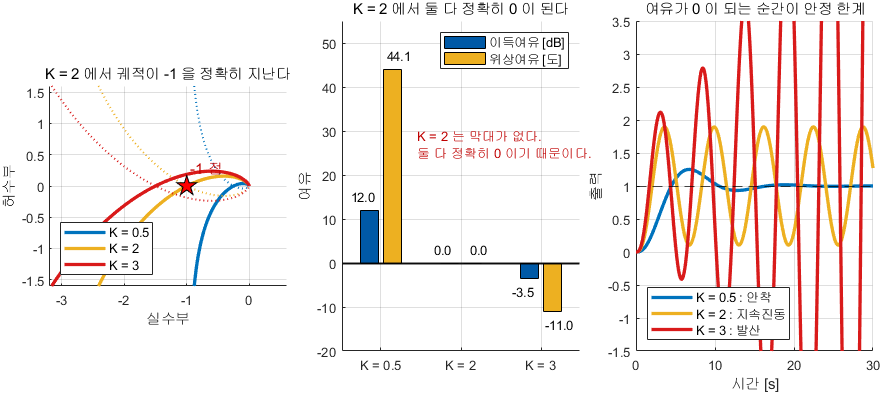

K = 0.5 / 2 / 3 을 나이퀴스트 · 여유 · 계단응답으로 한 번에

**그림 파일** `w09_gm_pm_three.png` — `make_figures.m` 의 `fig_w09_gm_pm_three` · 다시 만들려면 `make_figures('w09_gm_pm_three')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_gm_pm_three` **직접 확인해 보려면** — `W09_04_gm_pm_build.m` 의 **3절**

그림 해석 — **세 칸의 같은 색이 같은 **$K$** 입니다**

마지막 줄을 기억해 두십시오. **지속진동의 주파수는 **$\omega_{cg}$** 입니다.** 현장에서 "왜 이 주기로 떨리지?" 를 물을 때 가장 먼저 확인할 숫자입니다.

표의 숫자를 직접 뽑아 봅니다. 함수를 따로 만들지 않고 한 절에서 끝냅니다.

Kv  = [0.5; 2; 3];
GM  = zeros(3,1);  PM = zeros(3,1);  maxRe = zeros(3,1);
for i = 1:3
    L = Kv(i)*G;                            % 개루프
    [g, p] = margin(L);
    GM(i) = mag2db(g);                      % 이득여유 [dB]
    PM(i) = p;                              % 위상여유 [도]
    maxRe(i) = max(real(pole(feedback(L,1))));   % 폐루프 극점 실수부의 최댓값
end
table(Kv, GM, PM, maxRe)

**여유의 부호와 극점 실수부의 부호가 정확히 같이 움직입니다.** 여유가 양수면 극점이 좌반면, 음수면 우반면입니다. $K=2$ 에서는 여유도 $0$, 실수부도 $0$ 입니다. 주파수영역의 판정과 s 평면의 판정이 **같은 것을 다르게 보고 있을 뿐**입니다.

## 4. 여유가 얼마면 충분한가

실무 기준은 이렇습니다.

- 이득여유 $6$ dB 이상 (약 $2$ 배)

- 위상여유 $30^\circ \sim 60^\circ$

**왜 여유가 필요한가** — 모델은 반드시 틀리기 때문입니다.

- 부품이 노후하면 이득이 변한다

- 온도가 바뀌면 시정수가 변한다

- 계산 시간, 통신 지연, 센서 처리 시간이 위상을 깎는다

여유란 **그만큼 틀려도 버틴다** 는 보증입니다.

## 4-1. 위상여유를 시간지연으로 바꿔 읽기

위상여유는 추상적으로 느껴지지만, **시간지연으로 바꾸면 아주 구체적**입니다.

시간지연 $\tau$ 의 주파수응답은


$$e^{-j\omega\tau}$$


크기는 언제나 $1$ 입니다. **크기 곡선을 전혀 건드리지 않습니다.** 위상만 $-\omega\tau$ 만큼 깎습니다.

따라서 교차주파수 $\omega_{cp}$ 에서 위상여유를 다 까먹는 지연은


$$\tau_{max} = \frac{PM\,[\mathrm{rad}]}{\omega_{cp}}$$


즉 **"우리 설계는 몇 초의 지연까지 견딘다"** 를 숫자로 말할 수 있습니다. 통신 지연이나 계산 시간을 다룰 때 실무에서 그대로 쓰는 식입니다.

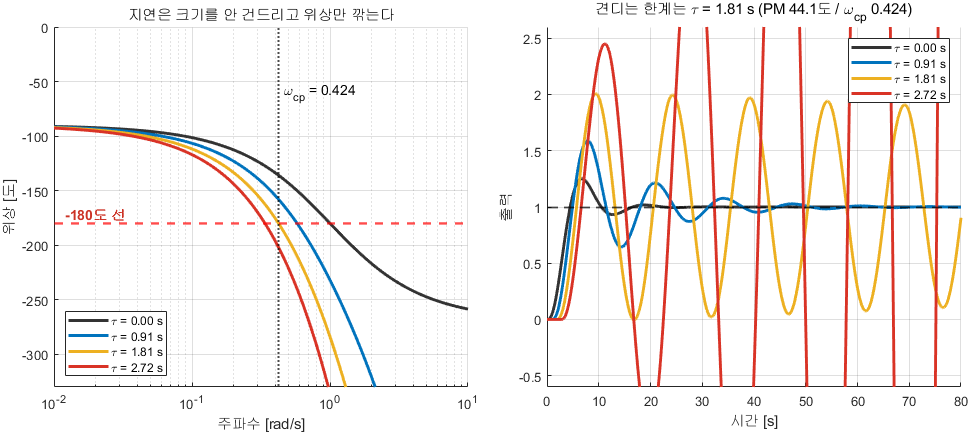

지연은 크기를 안 건드리고 위상만 깎는다

**그림 파일** `w09_delay.png` — `make_figures.m` 의 `fig_w09_delay` · 다시 만들려면 `make_figures('w09_delay')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_delay` **직접 확인해 보려면** — `W09_03_run_simulink.m` 이 Simulink 모델에 `Transport Delay` 를 넣고 같은 실험을 합니다

그림 해석

계산식으로 확인하면 $\tau_{max} = 44.1^\circ \times (\pi/180) / 0.424 = 1.81$ s 입니다. **그림의 노란 곡선이 정확히 그 값에서 안정 한계가 되었습니다.** 위상여유가 추상적으로 느껴질 때 이 변환을 쓰십시오.

K = [0.2 0.5 1.0]';
PM = zeros(size(K));  wcp = PM;
for i = 1:numel(K)
    [~, PM(i), ~, wcp(i)] = margin(K(i)*G);
end
delay_max = deg2rad(PM)./wcp;      % 견딜 수 있는 시간지연 [s]
table(K, PM, wcp, delay_max)

이득을 키우면 **견딜 수 있는 지연이 급격히 줄어듭니다.** 빠른 제어기일수록 지연에 약합니다. 공짜가 없습니다.

## 4-2. 개루프만 보고 폐루프를 알아내는 원리

**여기서 한 가지 의문이 생겨야 합니다.** 우리가 궁금한 것은 폐루프 $T$ 인데, 오늘 그린 것은 전부 개루프 $L$ 입니다. 나이퀴스트 선도도 $L$, 보드 선도도 $L$, 이득여유·위상여유도 $L$ 에서 읽었습니다.

**왜 개루프만 봐도 되는가?** 답은 $T$ 와 $L$ 의 관계식 한 줄에 있습니다.

**1단계 — 관계식을 세웁니다.** 단위 되먹임이므로 (0-2절의 신호 따라가기)


$$T(s) = \frac{L(s)}{1 + L(s)}$$


**2단계 — 두 가지 극단만 봅니다.** $T$ 는 $L$ 하나로 정해지므로 $|L|$ 이 아주 크거나 아주 작은 경우만 보면 대부분이 설명됩니다.

$|L| \gg 1$** (저주파) 인 경우** — 분모의 $1$ 은 $L$ 옆에서 무시할 수 있습니다.


$$T = \frac{L}{1 + L} \approx \frac{L}{L} = 1$$


$|L| \ll 1$** (고주파) 인 경우** — 이번에는 분모의 $L$ 이 $1$ 옆에서 무시됩니다.


$$T = \frac{L}{1 + L} \approx \frac{L}{1} = L$$


**3단계 — 숫자로 확인합니다.** $L = 100$ 이면


$$T = \frac{100}{1 + 100} = \frac{100}{101} = 0.990 \approx 1$$


$L = 0.01$ 이면


$$T = \frac{0.01}{1 + 0.01} = \frac{0.01}{1.01} = 0.0099 \approx 0.01 = L$$


**4단계 — 그래서 이렇게 읽습니다.**

마지막 줄이 오늘 수업의 핵심입니다. $|L|=1$ 근처는 근사가 통하지 않는 구간이고, 바로 그 구간에서 위상이 얼마인지에 따라 폐루프가 얌전할지 날뛸지가 갈립니다. **그래서 교차주파수 근처의 위상여유를 보는 것입니다.**

그리고 실제 플랜트는 거의 항상 **저주파에서 이득이 크고 고주파에서 작습니다** (적분기와 저역통과 성질 때문입니다). 그러므로 $|L|$ 곡선은 왼쪽이 높고 오른쪽이 낮은 내림 곡선이 되고, $|L|=1$ 을 **딱 한 번** 지나갑니다.

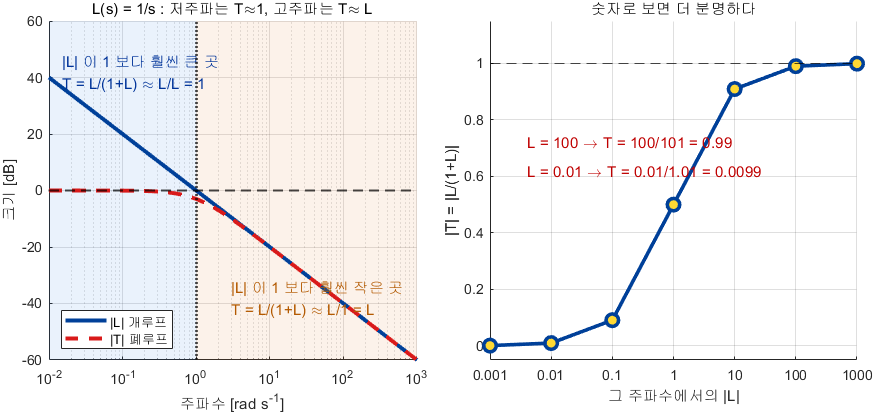

L 의 크기에 따라 T 가 1 에 붙거나 L 과 겹친다

**그림 파일** `w09_L_to_T.png` — `make_figures.m` 의 `fig_w09_L_to_T` · 다시 만들려면 `make_figures('w09_L_to_T')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_L_to_T` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **1절**

그림 해석 — **가장 단순한 **$L(s) = 1/s$** 로 봅니다**

함수를 쓰지 않고 식 한 줄로 확인합니다.

L_list = [0.001; 0.01; 0.1; 1; 10; 100; 1000];
T_list = L_list ./ (1 + L_list);          % T = L/(1+L)
ratio  = T_list ./ L_list;                % T 가 L 의 몇 배인가 (고주파에서 1)
table(L_list, T_list, ratio)

표의 `ratio` 열을 보십시오. $L$ 이 작을 때는 $1$ 에 가깝고 ($T \approx L$ 이라는 뜻), $L$ 이 클 때는 $0$ 에 가깝습니다 ($T$ 가 $1$ 에 멈춰 있는데 $L$ 만 커지기 때문입니다). **한 식이 두 가지 모습을 보이는 이유를 한 표로 볼 수 있습니다.**

## 4-3. 교차주파수와 대역폭 — 이름이 다른 두 주파수

비슷한 이름의 주파수가 두 개 나왔습니다. **서로 다른 것입니다.**

**왜 **$-3$** dB 인가** — 크기 $0.707$ 은 $1/\sqrt{2}$ 입니다. 데시벨로 바꾸면


$$20\log_{10}\frac{1}{\sqrt{2}} = -20 \times \frac{1}{2}\log_{10}2 = -10 \times 0.301 = -3.01 \;\mathrm{dB}$$


그리고 **전력은 크기의 제곱**이므로 $(1/\sqrt{2})^2 = 1/2$, 곧 **전력이 절반이 되는 주파수**입니다. 그래서 반전력 주파수라고도 부릅니다.

**두 주파수의 관계** — 4-2절의 결과를 그대로 씁니다. $\omega = \omega_c$ 에서는 $|L| = 1$ 이므로


$$|T(j\omega_c)| = \left|\frac{L}{1+L}\right| = \frac{1}{|1 + L(j\omega_c)|}$$


분모 $|1+L|$ 은 나이퀴스트 평면에서 $-1$** 점에서 궤적까지의 거리**입니다 (3절). 그 거리는 위상여유에 따라 달라지므로 $|T(j\omega_c)|$ 도 달라집니다. 다만 실용적인 설계 범위에서는 $|T(j\omega_c)|$ 가 $-3$ dB 근처에 놓이고, $|T|$ 는 그 뒤로 $L$ 을 따라 떨어집니다. 그래서 다음 어림이 성립합니다.


$$\omega_c \;\le\; \omega_{BW} \;\le\; 2\,\omega_c$$


**읽는 법** — 개루프에서 $0$ dB 교차점만 찾으면 **폐루프 대역폭을 1 배에서 2 배 사이로 가둘 수 있습니다.** 폐루프를 계산하지 않고도 "이 설계는 얼마나 빠른가" 를 즉시 답할 수 있다는 뜻입니다.

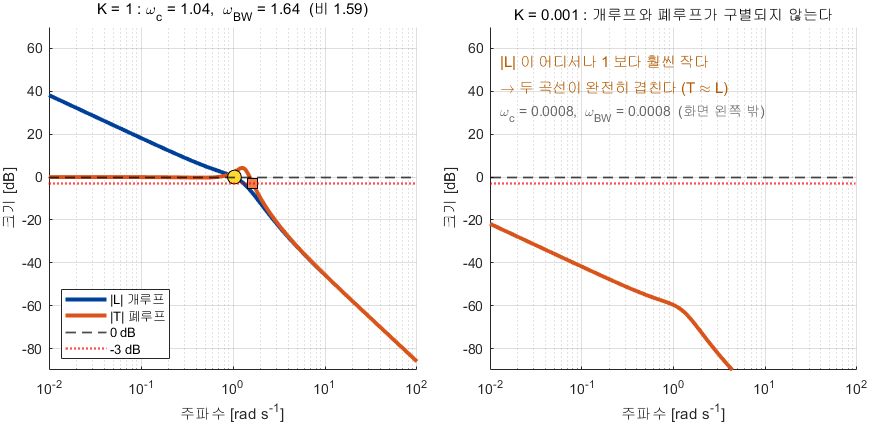

개루프 교차주파수와 폐루프 대역폭의 관계

**그림 파일** `w09_OL_CL.png` — `make_figures.m` 의 `fig_w09_OL_CL` · 다시 만들려면 `make_figures('w09_OL_CL')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_OL_CL` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **2절**

그림 해석

오른쪽 칸이 중요한 교훈입니다. 이득이 너무 작으면 개루프와 폐루프가 구별되지 않습니다. **되먹임이 의미를 가지려면 저주파에서 **$|L|$** 이 커야 합니다.**

숫자로 직접 재 봅니다. 이 절은 다른 절과 독립입니다.

s2 = tf('s');
G2 = (0.5*s2 + 1.3) / (s2^3 + 1.2*s2^2 + 1.6*s2);   % 이 절에서만 쓰는 플랜트
T2 = feedback(G2, 1);                                % 폐루프
[~, ~, ~, wc2] = margin(G2);                         % 개루프 0 dB 교차주파수
wbw2  = bandwidth(T2);                               % 폐루프 -3 dB 주파수
ratio = wbw2 / wc2                                   % 1 과 2 사이여야 한다

$1.59$ 가 나옵니다. $\omega_c \le \omega_{BW} \le 2\omega_c$ 안에 들어갑니다. 교차주파수 하나로 대역폭을 가늠할 수 있다는 것이 확인되었습니다.

**여기까지는 어림입니다.** 범위만 주고 그 안에서 어디인지는 말하지 못합니다. 이 절은 "$1$ 과 $2$ 사이" 까지만 하고, 뒤에서 두 번 더 조입니다.

즉 지금 쓴 "$-3$ dB 근처에 놓인다" 는 말이 $5$-$1$-$3$-$2$절에서 **정확히 몇 dB 인지** 로 바뀝니다. $PM = 60^\circ$ 면 $0$ dB, $PM = 90^\circ$ 면 꼭 $-3$ dB 입니다.

## 5. 시간영역 사양과의 번역

4주차에서 배운 시간영역 사양과 오늘의 주파수영역 사양은 **같은 것을 다르게 말하는 것**입니다. 서로 번역할 수 있습니다.

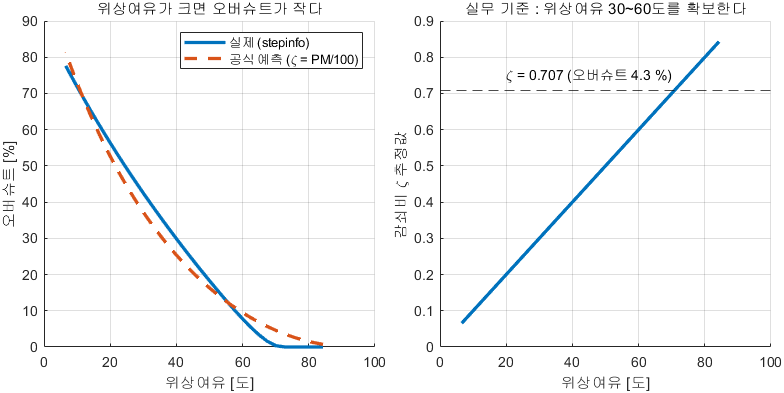

위상여유가 크면 오버슈트가 작다

**그림 파일** `w09_pm_os.png` — `make_figures.m` 의 `fig_pm_os` · 다시 만들려면 `make_figures('w09_pm_os')`

**만드는 곳** — `make_figures.m` 의 `fig_pm_os` **직접 확인해 보려면** — `W09_02_pm_to_time.m` 의 **1절**이 이득을 훑으며 PM 과 실제 오버슈트를 나란히 표로 찍어 줍니다

그림 해석

**외울 것은 **$\zeta \approx PM/100$** 한 줄입니다.** PM $30^\circ$ 면 $\zeta \approx 0.3$ (오버슈트 $37\%$), PM $60^\circ$ 면 $\zeta \approx 0.6$ (오버슈트 $9\%$) 로 어림합니다.

K = [0.2 0.4 0.6 0.8 1.0]';
PM = zeros(size(K));  OS_real = PM;
for i = 1:numel(K)
    [~, PM(i)] = margin(K(i)*G);
    OS_real(i) = stepinfo(feedback(K(i)*G, 1)).Overshoot;
end
zeta_est   = PM/100;                                        % 어림 규칙
OS_formula = 100*exp(-zeta_est*pi./sqrt(1-zeta_est.^2));    % 4주차 공식
table(K, PM, zeta_est, OS_formula, OS_real)

정확히 맞지는 않습니다. 3차 시스템이라 2차 공식이 어긋납니다. 그래도 **설계 초기에 짐작하기에는 충분합니다.** 설계를 마치면 반드시 `stepinfo` 로 검증해야 합니다.

## 5-1. 대역폭 — 빠르기의 주파수영역 표현

대역폭이란 폐루프 크기가 $-3$ dB 로 떨어지는 주파수입니다. "이 주파수까지는 지령을 따라간다" 는 뜻이므로 곧 **빠르기**입니다.

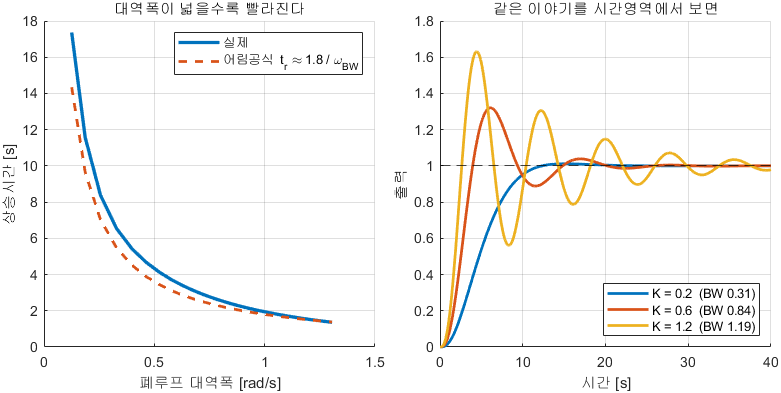

대역폭이 넓을수록 빠르다

**그림 파일** `w09_bw_speed.png` — `make_figures.m` 의 `fig_bw_speed` · 다시 만들려면 `make_figures('w09_bw_speed')`

**만드는 곳** — `make_figures.m` 의 `fig_bw_speed` **직접 확인해 보려면** — `W09_02_pm_to_time.m` 의 **2절**

그림 해석

왼쪽만 보면 "대역폭을 넓히면 좋다" 로 읽힙니다. **오른쪽을 함께 보십시오.** 대역폭을 넓히려고 이득을 키우면 위상여유가 깎여 오버슈트가 커집니다. 여기서도 공짜가 없습니다.

K = [0.2 0.5 1.0 1.4]';
bw = zeros(size(K));  rise_time = bw;
for i = 1:numel(K)
    T = feedback(K(i)*G, 1);
    bw(i)        = bandwidth(T);
    rise_time(i) = stepinfo(T).RiseTime;
end
rule_of_thumb = 1.8./bw;        % 어림 규칙 : 상승시간 = 1.8 / 대역폭
table(K, bw, rise_time, rule_of_thumb)

## 5-1-1. 공진 봉우리 — 폐루프 크기가 $1$ 을 넘는 자리

4-2절에서 "저주파에서 $T \approx 1$" 이라고 했습니다. 그런데 실제 폐루프 크기 곡선을 보면 $1$** 을 넘어 솟는 봉우리**가 있습니다. 그 꼭대기 값을 **공진 봉우리** $M_r$, 그 주파수를 **공진 주파수** $\omega_r$ 이라 합니다.

**왜 솟는가 — 비유부터.** 그네를 밀 때 아무 때나 밀면 잘 안 갑니다. **그네의 고유 주기에 맞춰** 밀면 조금만 밀어도 크게 흔들립니다. 폐루프도 똑같습니다. 어떤 주파수의 지령을 넣으면 **지령보다 큰 출력**이 나옵니다.

**유도** — 2차 표준형으로 계산합니다 (4주차에서 쓴 것과 같은 식입니다).


$$T(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2}$$


**1단계** $s = j\omega$ 를 넣고 $u = \omega/\omega_n$ 으로 정규화합니다.


$$T(j\omega) = \frac{1}{(1 - u^2) + j\,2\zeta u}$$


**2단계** 크기를 구합니다. 분모의 크기를 재면 됩니다.


$$M(u) = \frac{1}{\sqrt{(1-u^2)^2 + (2\zeta u)^2}}$$


**3단계** $M$ 이 가장 커지는 것은 **제곱근 안이 가장 작아질 때**입니다. 그래서 $f(u) = (1-u^2)^2 + 4\zeta^2 u^2$ 를 $u$ 로 미분해서 $0$ 으로 둡니다.


$$\frac{df}{du} = 2(1-u^2)(-2u) + 8\zeta^2 u = 4u\left[-(1-u^2) + 2\zeta^2\right] = 0$$


**4단계** $u \ne 0$ 인 해를 고릅니다.


$$u^2 = 1 - 2\zeta^2 \quad\Rightarrow\quad \omega_r = \omega_n\sqrt{1 - 2\zeta^2}$$


**5단계** 이 $u$ 를 $M(u)$ 에 되넣습니다. $1 - u^2 = 2\zeta^2$ 이고 $4\zeta^2u^2 = 4\zeta^2(1-2\zeta^2)$ 이므로


$$(1-u^2)^2 + 4\zeta^2u^2 = 4\zeta^4 + 4\zeta^2 - 8\zeta^4 = 4\zeta^2(1 - \zeta^2)$$



$$M_r = \frac{1}{\sqrt{4\zeta^2(1-\zeta^2)}} = \frac{1}{2\zeta\sqrt{1-\zeta^2}}$$


**6단계 — 가장 중요한 결론.** $\omega_r$ 식의 제곱근 안을 보십시오.


$$1 - 2\zeta^2 > 0 \quad\Rightarrow\quad \zeta < \frac{1}{\sqrt{2}} = 0.707$$


$\zeta \ge 0.707$** 이면 **$\omega_r$** 이 허수가 됩니다.** 실제 주파수가 아니라는 뜻, 곧 **봉우리가 아예 생기지 않는다**는 뜻입니다. 곡선이 그냥 내려갑니다.

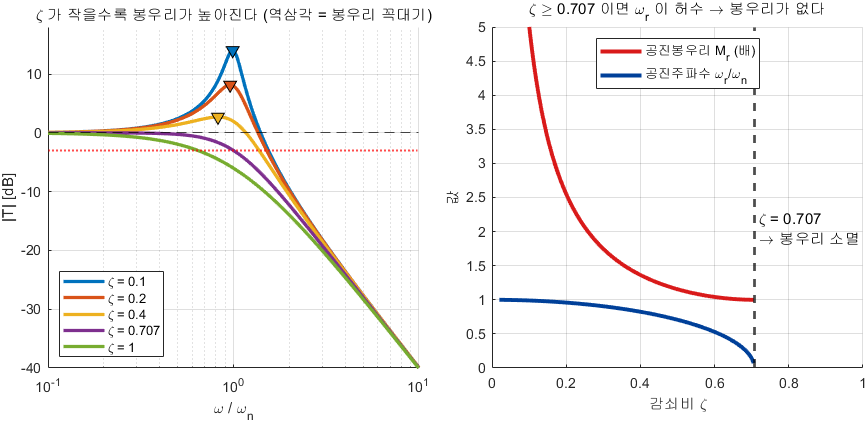

감쇠비가 작을수록 봉우리가 높고, 0.707 이상에서는 봉우리가 없다

**그림 파일** `w09_Mr_zeta.png` — `make_figures.m` 의 `fig_w09_Mr_zeta` · 다시 만들려면 `make_figures('w09_Mr_zeta')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_Mr_zeta` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **3절**

그림 해석

**실무에서 이렇게 씁니다.** 봉우리가 높다는 것은 그 주파수의 지령이나 외란에 **과민하다**는 뜻입니다. 설계 기준은 보통 $M_r \le 1.3$ 정도, $\zeta \ge 0.4$ 정도로 잡습니다. $\zeta = 0.707$ 이면 봉우리가 아예 없습니다.

공식과 실측을 대조합니다. 함수 없이 한 절에서 끝냅니다.

s3   = tf('s');
zlst = [0.1; 0.2; 0.4; 0.707];
Mr_formula = zeros(4,1);  Mr_measured = zeros(4,1);
for i = 1:4
    z = zlst(i);
    Tz = tf(1, [1, 2*z, 1]);                   % wn = 1 인 2차 표준형
    Mr_formula(i)  = 1/(2*z*sqrt(1-z^2));      % 유도한 공식
    Mr_measured(i) = max(abs(squeeze(freqresp(Tz, logspace(-1,1,2000)))));
end
table(zlst, Mr_formula, Mr_measured)

앞의 세 줄은 공식과 실측이 소수점 셋째 자리까지 같습니다. 마지막 줄 $\zeta = 0.707$ 에서는 공식이 $1.0$ 을 주고 실측도 $1.0$ 입니다. **봉우리가 없으니 최대값이 저주파의 **$1$** 그 자체**인 것입니다.

## 5-1-2. 대역폭을 $\omega_n$ 과 $\zeta$ 로 쓰면

5-1절에서 대역폭을 `bandwidth` 로 재었습니다. 2차 표준형에서는 **공식으로도** 쓸 수 있습니다. 같은 방법으로 유도합니다.

**1단계** 정의대로 식을 세웁니다. $M(u) = 1/\sqrt{2}$ 가 되는 $u$ 를 찾습니다.


$$\frac{1}{\sqrt{(1-u^2)^2 + (2\zeta u)^2}} = \frac{1}{\sqrt{2}}$$


**2단계** 양변을 뒤집고 제곱합니다.


$$(1-u^2)^2 + 4\zeta^2u^2 = 2$$


**3단계** $x = u^2$ 로 두면 $x$ 의 2차 방정식이 됩니다.


$$x^2 - 2x + 4\zeta^2 x + 1 - 2 = 0 \quad\Rightarrow\quad x^2 + (4\zeta^2 - 2)x - 1 = 0$$


**4단계** 근의 공식을 쓰고 **양수인 근**만 고릅니다.


$$x = (1 - 2\zeta^2) + \sqrt{4\zeta^4 - 4\zeta^2 + 2}$$


**5단계** $u = \sqrt{x}$, $\omega_{BW} = u\,\omega_n$ 이므로


$$\omega_{BW} = \omega_n\sqrt{1 - 2\zeta^2 + \sqrt{4\zeta^4 - 4\zeta^2 + 2}}$$


**이 식에서 읽을 두 가지**

- $\omega_n$ 이 앞에 곱으로 나와 있습니다 → **대역폭은 **$\omega_n$** 에 비례**합니다

- 제곱근 안은 $\zeta$ 만의 함수이고 $\zeta$ 가 커지면 작아집니다 → $\zeta$** 가 커지면 대역폭은 줄어듭니다**

**시간영역과의 연결** — 상승시간은 대역폭에 반비례합니다 ($t_r \approx 1.8/\omega_{BW}$). 정착시간과 첨두시간도 마찬가지입니다. 2차 표준형의 식을 그대로 보면


$$t_s \approx \frac{4}{\zeta\omega_n}, \qquad T_p = \frac{\pi}{\omega_n\sqrt{1-\zeta^2}}$$


셋 다 분모에 $\omega_n$ 이 있습니다. 그리고 $\omega_{BW}$ 도 $\omega_n$ 에 비례합니다. **그래서 셋 다 대역폭에 반비례합니다.** 거꾸로 읽으면 — **상승시간을 반으로 줄이려면 대역폭을 두 배로 넓혀야 합니다.**

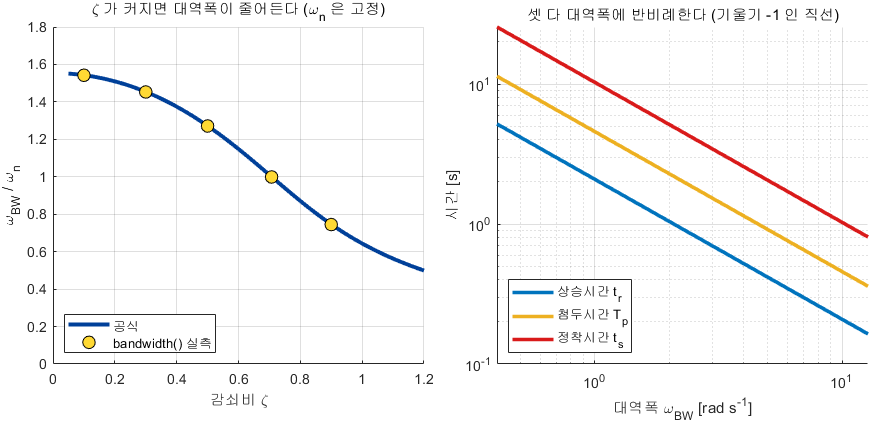

대역폭 공식과 시간영역 사양 세 가지

**그림 파일** `w09_bw_zeta.png` — `make_figures.m` 의 `fig_w09_bw_zeta` · 다시 만들려면 `make_figures('w09_bw_zeta')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_bw_zeta` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **4절**

그림 해석

공식과 실측을 대조합니다.

zb  = [0.1; 0.3; 0.5; 0.707; 0.9];
bw_formula  = sqrt(1 - 2*zb.^2 + sqrt(4*zb.^4 - 4*zb.^2 + 2));   % wn = 1
bw_measured = zeros(5,1);
for i = 1:5
    bw_measured(i) = bandwidth(tf(1, [1, 2*zb(i), 1]));
end
table(zb, bw_formula, bw_measured)

두 열이 일치합니다. **손으로 유도한 식이 맞다**는 확인입니다. 이제 $\zeta$ 와 $\omega_n$ 만 알면 대역폭을 계산기로 구할 수 있습니다.

## 5-1-3. 위상여유와 감쇠비 — 어림이 아닌 정확한 식

5절에서 $\zeta \approx PM/100$ 을 썼습니다. **어림입니다.** 2차 표준형에서는 정확한 식을 유도할 수 있습니다. 어림이 어디까지 믿을 만한지 알려면 정확한 식을 한 번은 봐야 합니다.

**1단계 — 개루프를 만듭니다.** 2차 표준형 폐루프 $T = \omega_n^2/(s^2+2\zeta\omega_n s+\omega_n^2)$ 를 만드는 개루프는 $T = L/(1+L)$ 을 거꾸로 풀면 나옵니다.


$$L = \frac{T}{1-T} = \frac{\omega_n^2}{s(s + 2\zeta\omega_n)}$$


**2단계 — 크기가 **$1$** 인 주파수를 찾습니다.** $s = j\omega$ 에서


$$|L| = \frac{\omega_n^2}{\omega\sqrt{\omega^2 + 4\zeta^2\omega_n^2}} = 1$$


양변을 제곱하고 $u = \omega/\omega_n$ 으로 정규화하면


$$u^4 + 4\zeta^2u^2 - 1 = 0 \quad\Rightarrow\quad u^2 = \sqrt{1+4\zeta^4} - 2\zeta^2$$



$$\frac{\omega_c}{\omega_n} = \sqrt{\sqrt{1+4\zeta^4} - 2\zeta^2}$$


**3단계 — 그 주파수의 위상을 잽니다.** $L$ 의 극점은 $0$ 과 $-2\zeta\omega_n$ 이므로


$$\angle L(j\omega) = -90^\circ - \tan^{-1}\frac{\omega}{2\zeta\omega_n}$$


**4단계 — 위상여유를 계산합니다.** 정의가 $PM = 180^\circ + \angle L(j\omega_c)$ 이므로


$$PM = 180^\circ - 90^\circ - \tan^{-1}\frac{u}{2\zeta} = 90^\circ - \tan^{-1}\frac{u}{2\zeta} = \tan^{-1}\frac{2\zeta}{u}$$


(마지막은 $\tan^{-1}a + \tan^{-1}(1/a) = 90^\circ$ 를 쓴 것입니다.)

**5단계 — **$u$** 를 2단계 결과로 바꿉니다.**


$$PM = \tan^{-1}\frac{2\zeta}{\sqrt{\sqrt{1+4\zeta^4} - 2\zeta^2}}$$


**손으로 한 번 넣어 봅니다.** $\zeta = 0.5$ 이면 $\sqrt{1+4(0.0625)} = \sqrt{1.25} = 1.118$, $2\zeta^2 = 0.5$ 이므로 $u = \sqrt{0.618} = 0.786$. 따라서


$$PM = \tan^{-1}\frac{1.0}{0.786} = \tan^{-1}1.272 = 51.8^\circ$$


어림식은 $\zeta \times 100 = 50^\circ$ 를 줍니다. $1.8^\circ$** 차이**입니다.

**왜 어림이 통하는가** — $\zeta$ 가 $0$ 에서 $0.6$ 사이일 때 위 곡선이 거의 직선이고 기울기가 약 $100$ 입니다. 그래서 $\zeta \approx PM/100$ 이 그 구간에서만 잘 맞습니다. $\zeta$ 가 커지면 곡선이 눕기 때문에 빗나갑니다.

**그리고 오버슈트로 이어집니다** (4주차 공식).


$$\%OS = 100\,e^{-\pi\zeta/\sqrt{1-\zeta^2}}$$


$PM$ 이 커지면 $\zeta$ 가 커지고, $\zeta$ 가 커지면 지수의 분자가 커져 $e^{-\text{큰 값}}$ 이 되므로 $\%OS$** 가 줄어듭니다.**

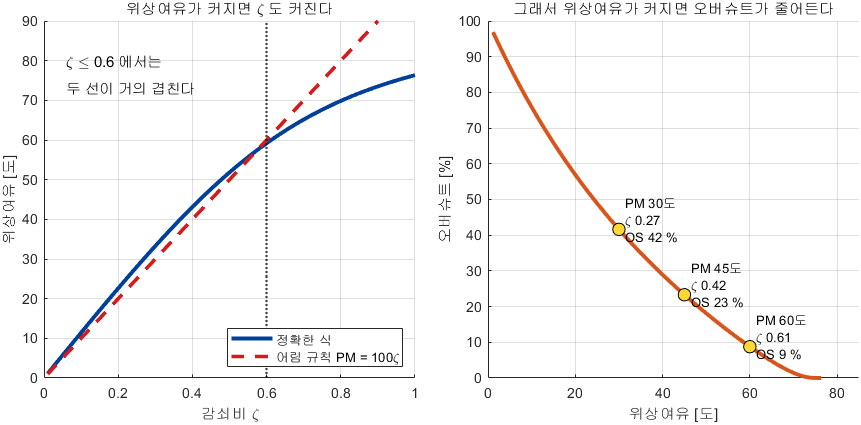

위상여유와 감쇠비의 정확한 관계, 그리고 오버슈트

**그림 파일** `w09_pm_zeta_exact.png` — `make_figures.m` 의 `fig_w09_pm_zeta_exact` · 다시 만들려면 `make_figures('w09_pm_zeta_exact')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_pm_zeta_exact` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **5절**

그림 해석

정확한 식 · 어림식 · 오버슈트를 한 표로 봅니다.

zp = [0.2; 0.3; 0.5; 0.7; 0.9];
u  = sqrt(sqrt(1 + 4*zp.^4) - 2*zp.^2);             % wc/wn
PM_exact = atan2(2*zp, u) * 180/pi;                 % 정확한 위상여유 [도]
PM_rule  = 100*zp;                                  % 어림식
OS_pct   = 100*exp(-pi*zp./sqrt(1 - zp.^2));        % 4주차 오버슈트 공식
table(zp, PM_exact, PM_rule, OS_pct)

$\zeta = 0.2 \sim 0.5$ 에서는 두 PM 열의 차이가 몇 도 이내입니다. $\zeta = 0.9$ 에서는 정확값 $75^\circ$ 에 어림값 $90^\circ$ — $15^\circ$** 차이**입니다. 그리고 `OS_pct` 열이 아래로 갈수록 줄어듭니다. **PM 이 커지면 오버슈트가 줄어든다**는 것이 세 열로 함께 확인됩니다.

## 5-1-3-1. 두 식을 나누면 — $\omega_{BW}$ 와 $\omega_c$ 의 정확한 비

왜 필요한가 — $4$-$3$절에서 두 주파수의 관계를 **어림**으로만 적었습니다.


$$\omega_c \le \omega_{BW} \le 2\omega_c$$


그런데 $5$-$1$-$2$절과 $5$-$1$-$3$절에서 **둘 다 정확한 식**을 이미 유도했습니다. 그러면 나누면 됩니다. 어림을 정확한 식으로 바꿀 수 있는데 어림으로 남겨 둘 이유가 없습니다.

**1단계 — 두 식을 나란히 적습니다.** 둘 다 $\omega_n$ 으로 정규화된 형태입니다. 왼쪽은 $5$-$1$-$2$절 (폐루프 $T$ 에서 $-3$ dB), 오른쪽은 $5$-$1$-$3$절 (개루프 $L$ 에서 $0$ dB) 입니다.


$$\frac{\omega_{BW}}{\omega_n} = \sqrt{(1 - 2\zeta^2) + \sqrt{4\zeta^4 - 4\zeta^2 + 2}}, \qquad \frac{\omega_c}{\omega_n} = \sqrt{\sqrt{1 + 4\zeta^4} - 2\zeta^2}$$


**2단계 — 나눕니다.** 분자와 분모에 $\omega_n$ 이 똑같이 들어 있으므로 **약분되어 사라집니다.** 이것이 중요한 지점입니다.


$$\frac{\omega_{BW}}{\omega_c} = \frac{\sqrt{(1 - 2\zeta^2) + \sqrt{4\zeta^4 - 4\zeta^2 + 2}}} {\sqrt{\sqrt{1 + 4\zeta^4} - 2\zeta^2}}$$


**3단계 — 읽습니다.** 오른쪽에 $\zeta$ 밖에 없습니다. 그러므로

- 비율은 $\omega_n$** 과 무관**합니다. 시스템이 느리든 빠르든 비율은 같습니다

- 비율은 $\zeta$** 만으로** 정해집니다. 감쇠비가 곧 두 주파수의 간격입니다

- 그러므로 $\omega_c$ 를 두 배로 키우면 $\omega_{BW}$ 도 **정확히 두 배**가 됩니다 ($\zeta$ 를 그대로 둔다면). $4$-$3$절에서 "비례처럼 움직인다" 고 말한 것의 **근거가 이 식**입니다

**손으로 한 번 넣어 봅니다.** $\zeta = 0.5$ 를 씁니다.

- 분자 : $1 - 2(0.25) = 0.5$, $4(0.0625) - 4(0.25) + 2 = 0.25 - 1 + 2 = 1.25$, $\sqrt{1.25} = 1.118$ $\rightarrow$ $\sqrt{0.5 + 1.118} = \sqrt{1.618} = 1.272$

- 분모 : $\sqrt{1 + 4(0.0625)} = \sqrt{1.25} = 1.118$, $2\zeta^2 = 0.5$ $\rightarrow$ $\sqrt{1.118 - 0.5} = \sqrt{0.618} = 0.786$

- 비율 : $1.272 / 0.786 = 1.618$

$\zeta = 0.5$ 에서 **대역폭은 교차주파수의 **$1.62$** 배**입니다. $4$-$3$절의 어림 범위 $[1, 2]$ 안에 들어 있고, 그 안에서 **어디인지** 까지 말해 줍니다.

표로 확인합니다. 손계산과 실측을 나란히 놓습니다.

s = tf('s');
zr = [0.1; 0.3; 0.5; 1/sqrt(2); 0.9];

wc_f  = sqrt(sqrt(1 + 4*zr.^4) - 2*zr.^2);                      % 5-1-3절 식
wbw_f = sqrt(1 - 2*zr.^2 + sqrt(4*zr.^4 - 4*zr.^2 + 2));        % 5-1-2절 식

wc_m  = zeros(5,1);  wbw_m = zeros(5,1);  PM_m = zeros(5,1);
for i = 1:5
    Li = 1/(s*(s + 2*zr(i)));                   % wn = 1 로 정규화한 개루프
    [~, PM_m(i), ~, wc_m(i)] = margin(Li);      % 개루프에서 읽는 wc
    wbw_m(i) = bandwidth(feedback(Li, 1));      % 폐루프에서 읽는 wBW
end

table(zr, wc_f, wc_m, wbw_f, wbw_m, wbw_f./wc_f, wbw_m./wc_m, PM_m, ...
    'VariableNames', {'zeta','wc_식','wc_실측','wBW_식','wBW_실측', ...
                      '비율_식','비율_실측','PM'})

네 가지를 읽습니다.

- `wc_식` 과 `wc_실측`, `wBW_식` 과 `wBW_실측` 이 각각 일치합니다. $5$**-**$1$**-**$2$**절과 **$5$**-**$1$**-**$3$**절의 유도가 둘 다 맞았습니다**

- `비율_식` 과 `비율_실측` 도 일치합니다. 나눈 것도 맞았습니다

- 비율이 $1.4 \sim 1.62$ 사이에서만 움직입니다. $\zeta$ 를 열 배로 바꿔도 비율은 $20\%$ 도 안 바뀝니다. **그래서 **$\omega_c$** 만 봐도 대역폭의 자리를 압니다**

- 비율이 가장 큰 곳이 $\zeta = 0.5$ 부근입니다. 양쪽으로 가면 줄어듭니다

## 5-1-3-2. 왜 $\omega_{BW}$ 가 $\omega_c$ 보다 큰가 — 위상여유로 설명된다

왜 필요한가 — 앞 절은 "비율이 $1.4 \sim 1.62$ 다" 라는 **숫자**를 줍니다. 그런데 **왜 **$1$** 보다 큰지**, 즉 왜 대역폭이 교차주파수보다 늘 오른쪽에 있는지는 아직 설명하지 않았습니다. 2차 표준형이라는 가정도 썼습니다. 이 절은 **2차라는 가정 없이** 답합니다. 그리고 답은 **위상여유**입니다.

**1단계 — **$\omega_c$** 에서 폐루프의 크기를 구합니다.** $T = L/(1+L)$ 의 크기는


$$|T(j\omega)| = \frac{|L(j\omega)|}{|1 + L(j\omega)|}$$


여기에 $\omega = \omega_c$ 를 넣습니다. $\omega_c$ 의 **정의**가 $|L(j\omega_c)| = 1$ 이므로 **분자가 **$1$** 이 되어 사라집니다.**


$$|T(j\omega_c)| = \frac{1}{|1 + L(j\omega_c)|}$$


**2단계 — 분모를 위상만으로 적습니다.** $|L| = 1$ 이므로 $L(j\omega_c)$ 는 **단위원 위의 점**입니다. 그 위상을 $\theta = \angle L(j\omega_c)$ 라 하면


$$L(j\omega_c) = \cos\theta + j\sin\theta$$


따라서 $1 + L$ 은 실수부가 $1 + \cos\theta$, 허수부가 $\sin\theta$ 입니다.


$$|1 + L(j\omega_c)| = \sqrt{(1 + \cos\theta)^2 + \sin^2\theta} = \sqrt{1 + 2\cos\theta + \cos^2\theta + \sin^2\theta} = \sqrt{2 + 2\cos\theta}$$


(마지막에서 $\cos^2\theta + \sin^2\theta = 1$ 을 썼습니다.)

**3단계 — 반각 공식으로 정리합니다.** $1 + \cos\theta = 2\cos^2(\theta/2)$ 이므로 $2 + 2\cos\theta = 4\cos^2(\theta/2)$ 입니다.


$$|1 + L(j\omega_c)| = 2\left|\cos\frac{\theta}{2}\right| \qquad\Rightarrow\qquad |T(j\omega_c)| = \frac{1}{2\left|\cos(\theta/2)\right|}$$


**4단계 — **$\theta$** 를 위상여유로 바꿉니다.** 정의가 $PM = 180^\circ + \theta$ 이므로 $\theta = -180^\circ + PM$ 이고 $\theta/2 = -90^\circ + PM/2$ 입니다. $\cos(-90^\circ + x) = \sin x$ 이므로


$$|T(j\omega_c)| = \frac{1}{2\sin(PM/2)}$$


**이것이 이 절의 결론입니다.** 왼쪽은 폐루프의 값, 오른쪽은 개루프에서 읽은 값 하나뿐입니다. 그리고 **플랜트의 차수·극점·영점이 식에 전혀 들어 있지 않습니다.** 2차든 5차든 똑같이 성립합니다.

**5단계 — 숫자를 넣어 읽습니다.**

표에서 **세 줄만 보면 답이 나옵니다.**

- $PM = 60^\circ$ 에서 폐루프가 **정확히 **$0$** dB** 입니다

- $PM = 90^\circ$ 에서 폐루프가 **정확히 **$-3$** dB** 입니다. 그런데 $-3$ dB 가 바로 대역폭의 정의입니다. 즉 $PM = 90^\circ$** 일 때 **$\omega_{BW} = \omega_c$** 로 정확히 같아집니다**

- $PM < 90^\circ$ 이면 $\omega_c$ 에서 폐루프는 **아직 **$-3$** dB 보다 위**에 있습니다. $|T|$ 는 주파수가 올라가면 내려가므로, $-3$ dB 를 만나는 곳은 $\omega_c$** 보다 오른쪽**입니다 $\rightarrow$ $\omega_{BW} > \omega_c$

**그러므로 이렇게 외웁니다.**

실무 설계의 위상여유는 $30^\circ \sim 70^\circ$ 입니다. 전부 $90^\circ$ 보다 작습니다. **그래서 현실의 시스템에서는 대역폭이 늘 교차주파수보다 큽니다.** $5$-$1$-$3$-$1$절의 비율이 전부 $1$ 보다 컸던 이유가 이것입니다.

**물리적 해석** — 같은 "빠르기" 를 서로 다른 두 자리에서 재는 것입니다.

- $\omega_c$ 는 **루프 안쪽**에서 잰 값입니다. "되먹임이 아직 힘을 쓰는 범위" 의 끝입니다. $\omega < \omega_c$ 에서는 $|L| > 1$ 이므로 오차를 눌러 주고, $\omega > \omega_c$ 에서는 $|L| < 1$ 이므로 손을 놓습니다. **설계자의 자**입니다 — 보드 선도 한 장에서 바로 읽힙니다

- $\omega_{BW}$ 는 **루프 밖에서** 잰 값입니다. 사용자는 루프 속을 못 봅니다. 지령을 흔들어 보고 출력이 따라오는지만 봅니다. **사양서의 자**입니다 — "이 시스템 얼마나 빠릅니까" 에 답합니다

- 둘을 잇는 것이 $\omega_c$** 근처에서 **$|1+L|$** 이 얼마인가**, 곧 **나이퀴스트 선도에서 **$-1$** 점까지의 거리**입니다. $3$절에서 안정여유를 그 거리로 정의했던 것이 여기서 다시 나옵니다. $-1$** 에서 멀면 (**$PM$** 이 크면) **$\omega_c$** 에서 폐루프가 이미 많이 내려와 있어 두 주파수가 가까워지고, **$-1$** 에 가까우면 (**$PM$** 이 작으면) **$\omega_c$** 에서 폐루프가 아직 봉우리 위라서 두 주파수가 멀어집니다**

- 그래서 $PM$ 이 작을수록 비율이 커집니다. $5$-$1$-$3$-$1$절 표의 `PM` 열과 `비율_실측` 열을 함께 보십시오. $PM$** 이 작은 줄에서 비율이 큽니다.** 같은 이야기를 두 번 한 것입니다

숫자로 확인합니다. 위 유도가 **2차에서만 맞는 것이 아님**을 보려고 일부러 3차 플랜트도 하나 섞습니다.

s = tf('s');

L_list  = { 1/(s*(s+1)), ...                      % 2차 (zeta = 0.5)
            4/(s*(s+4)), ...                      % 2차 (zeta = 1 — 감쇠가 더 크다)
            10/(s*(s+1)*(s+5)) };                 % 3차 — 유도가 차수에 무관함을 확인
L_name  = ["2차 a"; "2차 b"; "3차"];

PM_v = zeros(3,1); wc_v = zeros(3,1); wbw_v = zeros(3,1);
Tc_formula = zeros(3,1); Tc_direct = zeros(3,1);

for i = 1:3
    Li = L_list{i};
    [~, PM_v(i), ~, wc_v(i)] = margin(Li);
    Ti = feedback(Li, 1);
    wbw_v(i) = bandwidth(Ti);

    Tc_formula(i) = 1 / (2*sin(PM_v(i)/2 * pi/180));   % 4단계의 식
    Tc_direct(i)  = abs(freqresp(Ti, wc_v(i)));        % 직접 잰 값
end

table(L_name, PM_v, wc_v, wbw_v, wbw_v./wc_v, Tc_formula, Tc_direct, ...
    'VariableNames', {'개루프','PM','wc','wBW','비율','식으로','직접잰값'})

읽을 것 세 가지입니다.

- **식으로** 와 **직접잰값** 이 세 줄 모두 일치합니다. 마지막 줄이 3차인데도 맞습니다. **유도에 차수가 들어가지 않았으므로 당연합니다**

- 세 줄 모두 PM 이 $90^\circ$ 보다 작고, 그래서 `식으로` 열이 $0.707$ 보다 큽니다. 즉 $\omega_c$ 에서 폐루프가 아직 $-3$ dB 위입니다. 그 결과 `비율` 열이 전부 $1$ 보다 큽니다

- PM 이 가장 작은 줄에서 `식으로` 가 가장 크고 `비율` 도 가장 큽니다. $-1$** 점에 가까울수록 두 주파수가 벌어집니다**

왜 중요한가 — 사양서는 $\omega_{BW}$ 로 옵니다. 설계는 $\omega_c$ 로 합니다. 이 절의 식이 **둘 사이의 번역기**입니다. 사양이 "$\omega_{BW} \ge 60$ rad/s" 이면 비율 $1.5$ 로 나눠 "$\omega_c \ge 40$ rad/s 를 맞추자" 로 번역하고, 보드 선도에서 이득을 올려 $\omega_c$ 를 그 자리로 옮기면 됩니다 ($5$절의 $K$ 이야기). $11$주차 $3$-$3$-$1$절에서 이 번역을 설계 절차로 정리하고, $3$-$4$절에서 위상여유까지 함께 맞추는 법을 다룹니다.

## 5-1-4. 세 화살표로 한 장에 정리

지금까지 주파수영역에서 읽은 값 세 개가 모두 시간영역으로 번역되었습니다. **공통점이 하나 있습니다. 전부 **$\zeta$** 를 거쳐 갑니다.**

$\zeta$** 하나가 두 세계를 잇는 다리입니다.** 그래서 주파수영역에서 설계해도 시간영역 사양을 맞출 수 있습니다. 오늘 수업의 가장 큰 그림입니다.

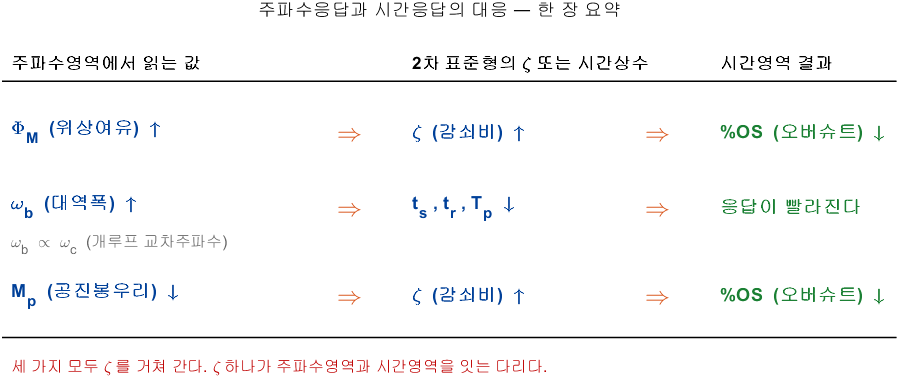

주파수영역 값 세 개가 모두 감쇠비를 거쳐 시간영역으로

**그림 파일** `w09_arrows.png` — `make_figures.m` 의 `fig_w09_arrows` · 다시 만들려면 `make_figures('w09_arrows')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_arrows` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **6절**

그림 해석

세 경로를 숫자 하나로 꿰어 봅니다. $\zeta$ 를 정하면 나머지가 전부 결정됩니다.

zA = 0.5;                                              % 감쇠비 하나만 정한다
u_A  = sqrt(sqrt(1 + 4*zA^4) - 2*zA^2);
PM_A = atan2(2*zA, u_A) * 180/pi                       % ① 위상여유 [도]
bw_A = sqrt(1 - 2*zA^2 + sqrt(4*zA^4 - 4*zA^2 + 2))    % ② 대역폭 (wn = 1)
Mr_A = 1/(2*zA*sqrt(1 - zA^2))                         % ③ 공진봉우리
OS_A = 100*exp(-pi*zA/sqrt(1 - zA^2))                  % 시간영역 오버슈트 [%]

$\zeta = 0.5$ 하나에서 네 숫자가 전부 나왔습니다. 거꾸로도 됩니다 — 측정으로 $PM$ 을 알면 $\zeta$ 를 알고, $\zeta$ 를 알면 오버슈트와 대역폭을 **재지 않고도** 짐작할 수 있습니다.

## 5-1-5. 개루프를 빠르게 하면 폐루프도 빨라진다

4-3절에서 $\omega_c \le \omega_{BW} \le 2\omega_c$ 를 보았습니다. 이 어림의 **설계적 의미**는 이것입니다.

**개루프 교차주파수 **$\omega_c$** 를 오른쪽으로 밀면 폐루프 대역폭도 함께 오른쪽으로 가고, 그러면 시간응답이 빨라집니다.**

그리고 $\omega_c$ 를 오른쪽으로 미는 방법은 3-2절에서 이미 보았습니다. **이득을 키우면 크기 곡선이 통째로 올라가므로 **$0$** dB 교차점이 오른쪽으로 옮겨 갑니다.** 세 절의 결과가 여기서 하나로 이어집니다.

$K$** 를 키우면 **$\Rightarrow$ $\omega_c$** 커짐 **$\Rightarrow$ $\omega_{BW}$** 커짐 **$\Rightarrow$ $t_r$**, **$t_s$**, **$T_p$** 줄어듦 (= 응답이 빨라짐)**

그러므로 **반응속도를 올리고 싶으면 손대야 할 것은 대역폭(또는 교차주파수) 하나입니다.** 8주차 5-5절에서 보드 선도로 확인한 그 평행이동이, 여기서 "폐루프가 얼마나 빨라지는가" 라는 숫자로 바뀝니다.

**단, 공짜가 아닙니다.** 이득을 키우면 위상여유가 깎입니다 (3-3절). 그래서 빠르게 하려는 만큼 오버슈트가 커집니다. 이 맞바꿈이 설계의 본질입니다.

먼저 $\zeta$** 를 고정하고 **$\omega_n$** 만 키우는** 가장 깨끗한 예로 "빠르기" 와 "대역폭" 이 같이 움직이는 것을 확인합니다. ($\zeta$ 를 고정했으므로 오버슈트는 세 경우 모두 똑같습니다.)

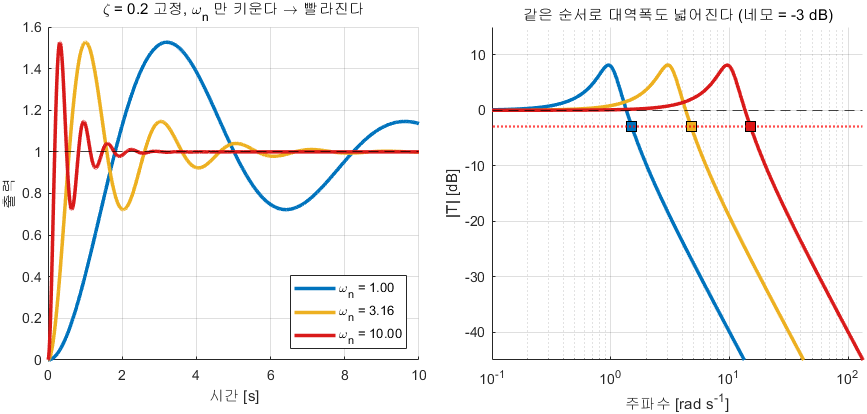

감쇠비를 고정하고 고유진동수만 키우면 응답과 대역폭이 함께 빨라진다

**그림 파일** `w09_wn_speed.png` — `make_figures.m` 의 `fig_w09_wn_speed` · 다시 만들려면 `make_figures('w09_wn_speed')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_wn_speed` **직접 확인해 보려면** — `W09_05_ol_to_cl.m` 의 **7절**

그림 해석

숫자로 확인합니다. 교수자 강의자료의 예제를 그대로 씁니다.

zeta_w = 0.2;
wn_w   = [1; sqrt(10); 10];
bw_w   = zeros(3,1);  tr_w = zeros(3,1);  os_w = zeros(3,1);
for i = 1:3
    w  = wn_w(i);
    Tw = tf(w^2, [1, 2*zeta_w*w, w^2]);        % 2차 표준형 폐루프
    bw_w(i) = bandwidth(Tw);
    info    = stepinfo(Tw);
    tr_w(i) = info.RiseTime;
    os_w(i) = info.Overshoot;
end
table(wn_w, bw_w, tr_w, os_w)

- `bw_w` 가 `wn_w` 와 **같은 비율**로 늘어납니다 — $\omega_{BW} \propto \omega_n$

- `tr_w` 는 **반대로 같은 비율로 줄어듭니다** — $t_r \propto 1/\omega_{BW}$

- `os_w` 는 **세 줄이 전부 같습니다** — 오버슈트는 $\zeta$ 만 정하기 때문

마지막 줄이 중요합니다. **빠르기와 출렁임은 서로 다른 다이얼**입니다. $\omega_n$ 은 빠르기, $\zeta$ 는 출렁임을 담당합니다.

## 5-1-6. 대역폭은 넓을수록 좋은가 — 맞바꿈

5-1-5절만 보면 "대역폭을 최대한 넓혀라" 로 읽힙니다. **아닙니다.** 대역폭을 정할 때 서로 반대로 당기는 요구가 셋 있습니다.

**① 지령을 따라가려면 넓어야 합니다.** 대역폭은 "이 주파수까지는 따라간다" 는 경계입니다. 지령에 들어 있는 주파수 성분이 대역폭 밖에 있으면 그 성분은 못 따라갑니다. **계단응답의 상승시간을 반으로 줄이려면 대역폭을 약 두 배로 넓혀야 합니다** ($t_r \approx 1.8/\omega_{BW}$).

**② 고주파 잡음을 막으려면 좁아야 합니다.** 센서 잡음은 대개 고주파입니다. 4-2절의 두 번째 근사를 떠올리십시오 — 고주파에서 $T \approx L$ 이므로, 대역폭 안에 있는 잡음은 **그대로 통과**합니다. 대역폭이 넓으면 그만큼 많은 잡음을 출력으로 들여보냅니다.

**③ 부품 값이 올라갑니다.** 대역폭이 넓다는 것은 **빠른 센서 · 빠른 구동기 · 높은 샘플링**을 쓴다는 뜻입니다. $\omega_{BW}$ 를 열 배로 늘리려면 센서 대역도 열 배, 샘플링 주기도 열 배입니다. **부품 값은 대역폭과 함께 올라갑니다.** 설계서에 반드시 적히는 제약입니다.

**그래서 "충분히 빠르면서 필요 이상으로 넓지 않게" 가 정답입니다.** 사양에서 요구하는 상승시간으로 $\omega_{BW}$ 의 **하한**을 정하고, 잡음과 비용으로 **상한**을 정한 뒤 그 사이에서 고릅니다.

이 맞바꿈을 수식으로 보는 것이 다음 절입니다. 감도함수 $S$ 와 폐루프 $T$ 가 **더해서 항상 **$1$ 이라는 사실이 위 표를 한 줄로 요약해 줍니다.

## 5-2. 근본적인 맞바꿈 — 감도함수

두 전달함수를 함께 봅니다. 그런데 그 전에 **잡음이 어디로 들어오는지**를 그림에서 확인해야 합니다. 외란과 들어오는 자리가 다릅니다.

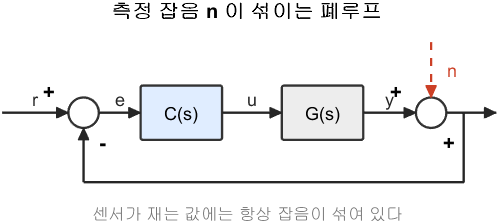

측정 잡음 n 은 출력 쪽 되먹임 경로로 들어온다

**그림 파일** `loop_noise.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_noise')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('noise', ...)` 로 부릅니다

그림 해석

이제 두 전달함수를 유도합니다. 신호를 따라가면 됩니다.


$$e = r - (y + n), \qquad y = L\,e$$


둘째를 첫째에 넣고 $y$ 를 한쪽으로 모읍니다.


$$y = L\,(r - y - n) \;\Rightarrow\; (1+L)\,y = L\,r - L\,n \;\Rightarrow\; y = \frac{L}{1+L}\,r - \frac{L}{1+L}\,n$$


그리고 오차는 (1주차 · 5주차와 같은 방법으로)


$$e = \frac{1}{1+L}\,r$$


여기 나온 두 덩어리에 이름을 붙인 것이 전부입니다.


$$S(s) = \frac{1}{1+L}, \qquad T(s) = \frac{L}{1+L}$$


$T$ 의 이름에 "상보" 가 붙은 이유는 한 줄이면 나옵니다. 두 분수의 **분모가 같으므로 그냥 더하면** 됩니다.


$$S + T = \frac{1}{1+L} + \frac{L}{1+L} = \frac{1 + L}{1+L} = 1$$



$$S(j\omega) + T(j\omega) = 1 \qquad \text{(모든 주파수에서)}$$


**이것이 제어의 근본적인 맞바꿈입니다.** 둘 다 작게 만들 수는 없습니다. $S$ 를 $0.01$ 로 만들면 그 주파수에서 $T$ 는 자동으로 $0.99$ 가 됩니다. 우리가 고를 수 있는 것은 **어느 주파수에서 어느 쪽을 작게 할 것인가**뿐입니다.

실무의 해법은 **주파수를 나눠 쓰는 것**입니다.

- 저주파에서 $S$ 를 작게 $\rightarrow$ 외란 억제, 정상상태 오차 감소

- 고주파에서 $T$ 를 작게 $\rightarrow$ 측정 잡음 억제

- 교차주파수 근처는 어쩔 수 없다. 그래서 **교차주파수를 어디에 둘 것인가**가 설계다

이득을 키우면 저주파의 $|S|$ 는 좋아지는데 교차주파수 근처의 봉우리가 솟습니다. 그 봉우리가 위상여유와 정확히 반대로 움직입니다.

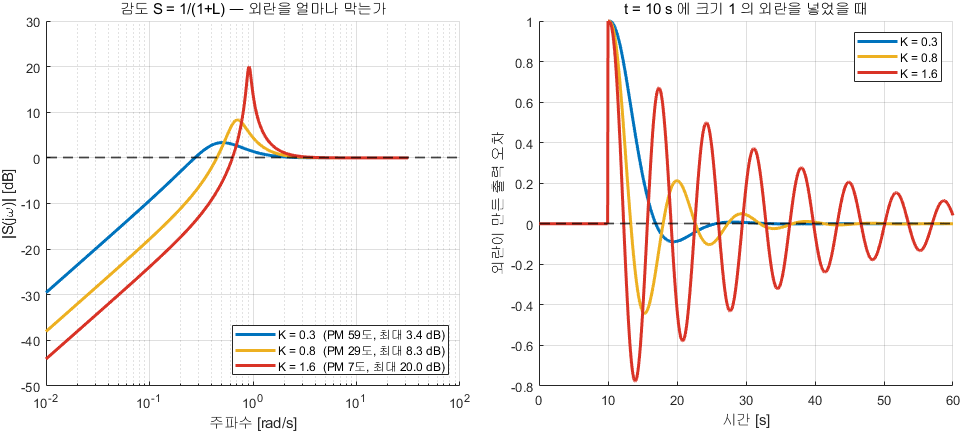

감도의 봉우리와 위상여유는 같은 이야기다

**그림 파일** `w09_sensitivity.png` — `make_figures.m` 의 `fig_w09_sensitivity` · 다시 만들려면 `make_figures('w09_sensitivity')`

**만드는 곳** — `make_figures.m` 의 `fig_w09_sensitivity` **직접 바꿔 보려면** — 함수 안의 `Ks = [0.3 0.8 1.6]` 을 바꿔 실행

그림 해석

**왼쪽 그림의 봉우리가 오른쪽 그림의 진동입니다.** $|S|$ 를 저주파에서 낮추려고 이득을 키우면, 그 대가로 교차주파수 근처에서 봉우리가 솟습니다. 봉우리를 $6$ dB ($2$ 배) 이하로 두라는 것이 실무 기준입니다.

Lx = 0.5*G;  Sx = 1/(1+Lx);  Tx = feedback(Lx,1);
w  = logspace(-2, 1.5, 400);
semilogx(w, 20*log10(squeeze(abs(freqresp(Sx,w)))), 'LineWidth', 2.2); hold on; grid on;
semilogx(w, 20*log10(squeeze(abs(freqresp(Tx,w)))), 'LineWidth', 2.2);
yline(0,'k--');
xlabel('주파수 [rad s^{-1}]'); ylabel('크기 [dB]');
legend('감도 S (외란)', '상보감도 T (잡음)', '0 dB', 'Location','east');
title('S 와 T 는 동시에 작아질 수 없다');

## 6. Simulink 모델에서 여유 뽑아내기

실제 현장에서 모델은 전달함수로 오지 않습니다. **블록선도로 옵니다.** 비선형 블록이 섞여 있고 서브시스템이 여러 겹입니다.

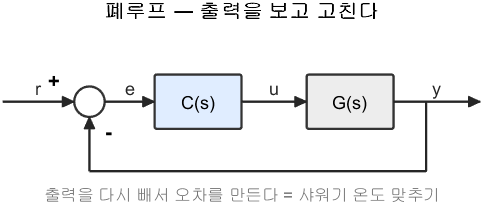

선형화의 대상은 이런 폐루프다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('closed', ...)` 로 부릅니다 **직접 해 보려면** — `W09_03_run_simulink.m` 이 `W09_Margin_Check.slx` 에서 이 루프를 잘라 개루프를 뽑습니다

그림 해석 — **오늘은 "어디를 자를 것인가" 를 정하는 그림입니다**

`margin` 은 **개루프** 를 받습니다. 그래서 Simulink 모델에서도 반드시 루프를 끊어 $L$ 을 만든 뒤에 여유를 재야 합니다. 폐루프를 넣으면 엉뚱한 값이 나옵니다.

이때 쓰는 것이 **선형화**입니다. 절차는 두 줄입니다.

- `linio` 로 **어디를 자를 것인가**를 지정한다 (루프를 끊어야 개루프가 된다)

- `linearize` 로 그 두 점 사이의 전달함수를 얻는다

`linio` — **자를 자리를 표시하는 명령**

- **하는 일** — 모델의 어느 블록 어느 포트를 입력/출력으로 볼지 정한다

- **입력** — `linio('모델/블록이름', 포트번호, 종류)`. 종류는 `'openinput'`(여기서 끊고 넣는다), `'openoutput'`(여기서 끊고 본다) 등

- **출력** — 선형화 지점 객체. 여러 개를 배열로 묶어 `linearize` 에 준다

`linearize` — **실제로 선형화하는 명령**

- **하는 일** — 지정한 두 점 사이를 수치적으로 미분해 상태공간 모델을 만든다

- **입력** — `linearize('모델이름', io)`

- **출력** — `ss` 객체. 그대로 `margin`, `bode` 에 넣으면 된다

주의

- 자르는 종류를 `'input'`/`'output'`(끊지 않음)으로 주면 **폐루프**가 나옵니다. 개루프를 원하면 반드시 `open` 이 붙은 것을 쓰십시오

- 모델이 **평형점에 있어야** 제대로 된 선형화가 나옵니다

## 6-1. 함정 — `linearize` 는 기본적으로 시간지연을 근사한다

4-1절에서 위상여유를 시간지연으로 바꿔 읽었습니다. 그런데 Simulink 모델에 `Transport Delay` 블록을 넣고 그대로 `linearize` 하면 **지연이 결과에 반영되지 않습니다.**

기본 설정이 지연을 유리수 함수로 근사(파데 근사)하는데, 차수가 $0$ 이면 아예 무시해 버리기 때문입니다.

실제로 이 과목을 만들 때 겪은 일입니다 — 지연을 $0$ 초에서 $1$ 초까지 바꿔 가며 `linearize` 를 불렀는데 **위상여유가 **$44.06^\circ$** 로 꼼짝도 안 했습니다.**

`linearizeOptions` — **그 설정을 바꾸는 명령**

- **하는 일** — 선형화 방식을 정하는 옵션 묶음을 만든다

- **입력** — 이름-값 쌍. 오늘 쓰는 것은 `'UseExactDelayModel'`

- **출력** — 옵션 객체. `linearize(모델, io, opt)` 처럼 세 번째 인자로 준다

쓰는 법은 한 줄입니다.

`opt = linearizeOptions('UseExactDelayModel', 'on');`

이렇게 하면 지연을 근사하지 않고 **그대로** 다룹니다. 그러면 위상여유가 지연에 따라 제대로 깎입니다. $\tau = 1$ 초에서 $44.06^\circ \rightarrow 19.78^\circ$ 로, 이론값 $44.06 - 180\cdot 1 \cdot 0.424/\pi = 19.78$ 과 정확히 맞습니다.

**교훈** — 도구가 조용히 근사하고 있을 수 있습니다. 결과가 "너무 안 변하면" 옵션을 의심하십시오.

3주차에서 손으로 한 야코비안 선형화를 도구가 대신 해 주는 것입니다.

실습 스크립트에서 확인할 것

- `W09_01_nyquist_margin.m` — 나이퀴스트, 여유, 개루프가 불안정한 경우

- `W09_02_pm_to_time.m` — 시간영역과의 번역표, 감도함수

- `W09_03_run_simulink.m` — `W09_Margin_Check.slx` 를 선형화해 여유를 뽑고, **시간지연을 키우며 위상여유가 깎이는 것**을 확인

마지막 스크립트의 결과를 미리 보면 이렇습니다. 지연이 $1.81$ 초를 넘으면 발산하는데, 그 값이 정확히 $PM/\omega_{cp}$ 입니다.

## 6-2. `margin` 과 `allmargin` — 여유를 숫자로 받는 법

`margin` 도 출력을 받느냐 안 받느냐로 하는 일이 갈립니다.

**가장 흔한 실수** — `Gm` 은 dB 가 아니라 **배수**입니다. 보드 선도에 적힌 dB 값과 맞추려면 `mag2db(Gm)` 를 해야 합니다.

`allmargin` 이 돌려주는 것

- `GainMargin`, `GMFrequency` — 이득여유와 그 주파수

- `PhaseMargin`, `PMFrequency` — 위상여유와 그 주파수

- `DelayMargin`, `DMFrequency` — **얼마나 지연되어도 버티는가** (초)

- `Stable` — 폐루프가 안정이면 1

마지막 두 개가 실무에서 특히 유용합니다. 통신 지연이나 센서 처리 시간이 있는 시스템에서 바로 쓸 수 있는 숫자입니다.

s = tf('s');
Lm = 1/(s*(s+1)^2);
[gm, pm, wcg, wcp] = margin(Lm);
gm_dB = mag2db(gm)              % 이득여유 [dB]
pm                              % 위상여유 [도]

am = allmargin(Lm);
delay_margin = am.DelayMargin   % 견딜 수 있는 지연 [s]
is_stable    = am.Stable        % 1 이면 폐루프가 안정

지연여유는 **위상여유를 교차주파수로 나눈 것**과 같습니다.

delay_check = deg2rad(pm)/wcp

## 6-3. 오늘 배운 것을 한 시스템에 전부 — 이득을 고르는 절차

**왜 이 절이 필요한가.** 지금까지 도구를 하나씩 배웠습니다. `nyquist`, `margin`, `bandwidth`, `stepinfo`, 그리고 $\zeta \approx PM/100$ 이라는 번역식. 그런데 **실무에서는 이 도구들을 한 줄로 이어서 씁니다.** "이득을 얼마로 할까" 라는 질문 하나에 전부 동원되는 것입니다.

이 절은 교수자 강의자료 68~72쪽에 있는 순서를 그대로 따라갑니다. MathWorks 문서 [Assessing Gain and Phase Margins](https://kr.mathworks.com/help/control/ug/assessing-gain-and-phase-margins.html) 의 예제와 같은 시스템입니다.

**오늘의 플랜트.** 영점이 하나 있고 원점에 극점이 하나 있는 3차 시스템입니다.


$$G(s) = \frac{0.5s + 1.3}{s^3 + 1.2s^2 + 1.6s}$$


분모를 $s(s^2 + 1.2s + 1.6)$ 으로 묶어 보면 구조가 보입니다.

- $s$ 가 하나 — **적분기**입니다. 계단 입력에 정상상태 오차가 $0$ 이 됩니다 (5주차)

- $s^2 + 1.2s + 1.6$ — $\omega_n = \sqrt{1.6} = 1.2649$, $\zeta = 0.6/1.2649 = 0.4743$

- 분자의 $0.5s + 1.3$ — 영점이 $s = -2.6$ 에 하나

**일곱 걸음.** 아래 순서가 이 절의 전부입니다. 걸음마다 쓰는 명령을 적어 둡니다.

실습 : `W09_06_margin_design.m` 의 **1절**

**걸음 1~5 를 **$K=1$** 에서.** 먼저 손에 쥐어야 할 숫자들입니다.

4절의 기준표에 대보면 **GM **$8.77$** dB (기준 **$6$** dB 이상), PM **$44.7^\circ$** (기준 **$30^\circ \sim 60^\circ$**)** — 둘 다 합격입니다. 여기서 끝내도 됩니다. 그런데 걸음 6, 7 이 남았습니다. 주파수영역에서 합격이라는 말이 **시간영역에서 무엇을 뜻하는지** 아직 확인하지 않았습니다.

**걸음 6 — 계단응답.** `stepinfo` 가 돌려주는 값은 이렇습니다.

**걸음 7 — 예측과 실측을 맞춰 본다.** 이것이 이 절의 핵심입니다. 5-1-3절에서 배운 어림식 $\zeta \approx PM/100$ 과 4주차의 오버슈트 공식을 이어 붙이면, **계단응답을 구해 보지 않고도** 오버슈트를 짐작할 수 있습니다.

두 식을 순서대로 적습니다.


$$\zeta \approx \frac{PM}{100} = \frac{44.67}{100} = 0.4467$$



$$\%OS = 100 \exp\left(-\frac{\zeta \pi}{\sqrt{1-\zeta^2}}\right)$$


손으로 넣어 봅니다. $\sqrt{1 - 0.4467^2} = \sqrt{0.8004} = 0.8946$ 이므로 지수부는 $-0.4467 \times 3.1416 / 0.8946 = -1.5689$ 이고, $100 e^{-1.5689} = 20.83\,\%$ 입니다.

**개루프 보드 선도의 숫자 하나(**$PM$**)로 폐루프 오버슈트를 소수점까지 맞혔습니다.** 4-2절에서 "개루프만 보고 폐루프를 알아낸다" 고 했던 것이 바로 이 장면입니다.

왜 이렇게 잘 맞는지도 짚어 둡니다. 5-1-3절에서 본 대로 어림식 $\zeta \approx PM/100$ 은 **표준 2차 시스템**에서 나온 것입니다. 이 시스템은 3차인데도 맞는 이유는, 폐루프 극점 세 개 중 $-0.2305 \pm 1.3062j$ 가 허수축에 훨씬 가까워 **그 두 개가 응답을 지배**하기 때문입니다 (2주차 지배극점). 실축 극점 $-0.7389$ 는 세 배 이상 멀리 있습니다.

실습 : `W09_06_margin_design.m` 의 **2절**

**이제 **$K$** 를 흔들어 봅니다.** 3-2절의 결론 1, 2 를 그대로 적용하면 결과를 그리기 전에 방향을 미리 말할 수 있습니다.

- 크기 선도만 통째로 올라간다 $\Rightarrow$ $0$ dB 교차점이 오른쪽으로 간다

- 위상 선도는 그대로 $\Rightarrow$ 그 오른쪽 자리의 위상은 더 아래에 있다

- 그러므로 $K$** 를 키우면 **$PM$** 이 줄어든다**

- $PM$ 이 줄면 $\zeta$ 가 줄고 $\Rightarrow$ 오버슈트가 커진다

- 동시에 $\omega_c$ 가 커지므로 $\Rightarrow$ 상승시간은 짧아진다

$K = 0.7$ 과 $K = 1.2$ 로 확인합니다.

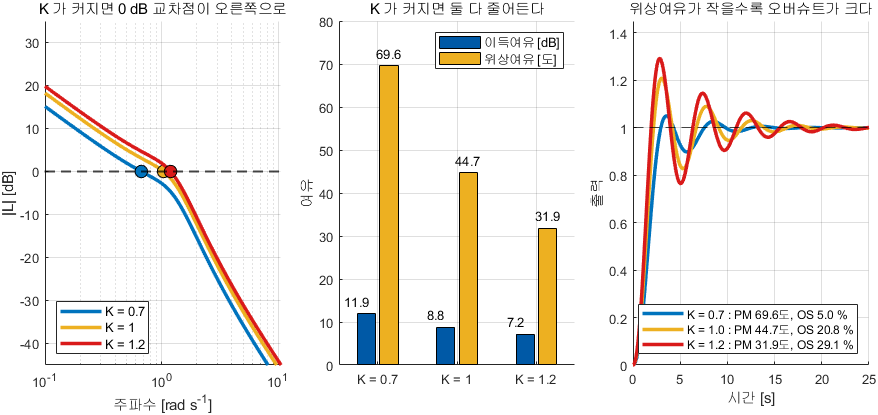

이득 K 를 바꾸면 여유와 응답이 어떻게 맞바뀌는가 (K = 0.7 / 1 / 1.2)

그림 해석

숫자로 적으면 이렇습니다. 가운데 두 열이 **주파수영역**, 오른쪽 세 열이 **시간영역**입니다.

이 표에서 읽을 것이 네 가지 있습니다.

- **GM 과 PM 이 같이 움직인다.** $K$ 를 $0.7$ 에서 $1.2$ 로 올리는 동안 GM 은 $11.87 \rightarrow 7.18$ dB, PM 은 $69.6^\circ \rightarrow 31.9^\circ$ 로 둘 다 줄어듭니다

- $t_r$** 은 짧아진다.** $1.86 \rightarrow 1.23$ s. 이것이 $K$ 를 키우는 **이유**입니다

- $\%OS$** 는 커진다.** $4.98 \rightarrow 29.11\,\%$. 이것이 $K$ 를 키우는 **대가**입니다

- $t_s$** 는 거꾸로 길어진다.** $9.03 \rightarrow 17.12$ s. 빨리 올라가지만 꼭짓점을 크게 넘어서서 가라앉는 데 더 오래 걸립니다

네 번째가 특히 중요합니다. **"빠르다" 가 한 가지 뜻이 아닙니다.** 처음 올라가는 속도($t_r$)와 자리를 잡는 속도($t_s$)는 서로 반대로 갈 수 있습니다. 사양서에 둘 중 무엇이 적혀 있는지를 보고 $K$ 를 골라야 합니다.

**예측식이 깨지는 자리도 보입니다.** $K = 1.2$ 에서 예측 $34.80\,\%$, 실측 $29.11\,\%$ — $5.7$ 포인트나 벌어졌습니다. $\zeta \approx PM/100$ 은 5-1-3절에서 본 대로 $PM$ 이 작아질수록 틀어지는 어림식입니다. **어림식은 방향을 보는 데 쓰고, 최종 확인은 stepinfo 명령으로 합니다.**

실습 : `W09_06_margin_design.m` 의 **3절**

## 7. 오늘의 정리

- 불안정의 조건은 $L(j\omega) = -1$. **여유란 그 점에서 얼마나 떨어졌는가**다

- 나이퀴스트 선도는 크기와 위상을 한 평면에 그린 것이다

- 나이퀴스트 판정 $Z = N + P$. 개루프가 안정하면 $-1$ 을 감지 않아야 한다

- **이득여유는 **$-180^\circ$** 인 곳에서, 위상여유는 **$0$** dB 인 곳에서** 읽는다

- 실무 기준은 GM $6$ dB 이상, PM $30^\circ \sim 60^\circ$

- 위상여유는 **견딜 수 있는 시간지연**으로 바꿔 읽을 수 있다

- 시간영역 사양과 주파수영역 사양은 서로 번역된다 ($\zeta \approx PM/100$)

- $S + T = 1$ 은 피할 수 없다. 주파수를 나눠 쓴다

그리고 **이득 **$K$** 를 손에 쥐었을 때** 오늘 노트가 답해 주는 것

- $K$ 를 키우면 **크기 선도만 통째로 올라가고 위상 선도는 꼼짝도 않는다** ($20\log_{10}|KG| = 20\log_{10}K + 20\log_{10}|G|$, $\angle(KG) = \angle G$)

- 그래서 $0$ dB 교차주파수 $\omega_c$ 가 오른쪽으로 밀리고, 따라오는 폐루프 대역폭 $\omega_{BW}$ 도 같이 커진다 ($\omega_c \le \omega_{BW} \le 2\omega_c$)

- **반응속도를 올리려면 결국 손대야 할 것은 대역폭(또는 교차주파수) 하나다** ($t_r \approx 1.8/\omega_{BW}$)

- 대가가 있다. **위상여유가 깎이고 오버슈트가 커진다.** 공짜는 없다

- 그래서 설계는 "빠르게" 가 아니라 **"사양을 만족하는 가장 느린 것"** 을 고르는 일이다

- 어림식($\zeta \approx PM/100$)은 **방향을 보는 데** 쓰고, 최종 확인은 반드시 `stepinfo` 로 한다 (6-3절에서 $K=1.2$ 가 그 예다)

## 8. 다음 주 예고

지금까지는 **판단**만 했습니다. 다음 주에는 **설계**합니다.

사양이 이렇게 주어집니다.

- 정상상태 오차 $\le$ 얼마

- 위상여유 $\ge$ 얼마

그러면 보상기를 이렇게 고릅니다.

- 위상이 모자라다 $\rightarrow$ **Lead** (위상을 끌어올린다)

- 저주파 이득이 모자라다 $\rightarrow$ **Lag** 또는 **PI**

7주차의 근궤적 설계와 목적은 같습니다. 도구만 다릅니다.